# ELEC5305 Project - Flute Reference Audio Analysis

clear;
clc;
close all;

## File paths

%% File paths

projectRoot = 'C:\Users\15023\Desktop\ELEC5305_Project';

files = {
    fullfile(projectRoot,'data','flute','Flute.nonvib.ff.C4.stereo.aif')
    fullfile(projectRoot,'data','flute','Flute.nonvib.ff.E4.stereo.aif')
    fullfile(projectRoot,'data','flute','Flute.nonvib.ff.A4.stereo.aif')
};

notes = {'C4', 'E4', 'A4'};

## Load audio

for i = 1:length(files)

    [x, fs] = audioread(files{i});

    % Convert stereo to mono if necessary
    if size(x,2) == 2
        x = mean(x,2);
    end

    % Normalise amplitude
    x = x / max(abs(x));

    fprintf('%s: Fs = %d Hz, Duration = %.2f s\n', ...
        notes{i}, fs, length(x)/fs);

end

C4: Fs = 44100 Hz, Duration = 2.47 s
E4: Fs = 44100 Hz, Duration = 2.75 s
A4: Fs = 44100 Hz, Duration = 2.38 s


## Waveform and FFT Spectrum Analysis

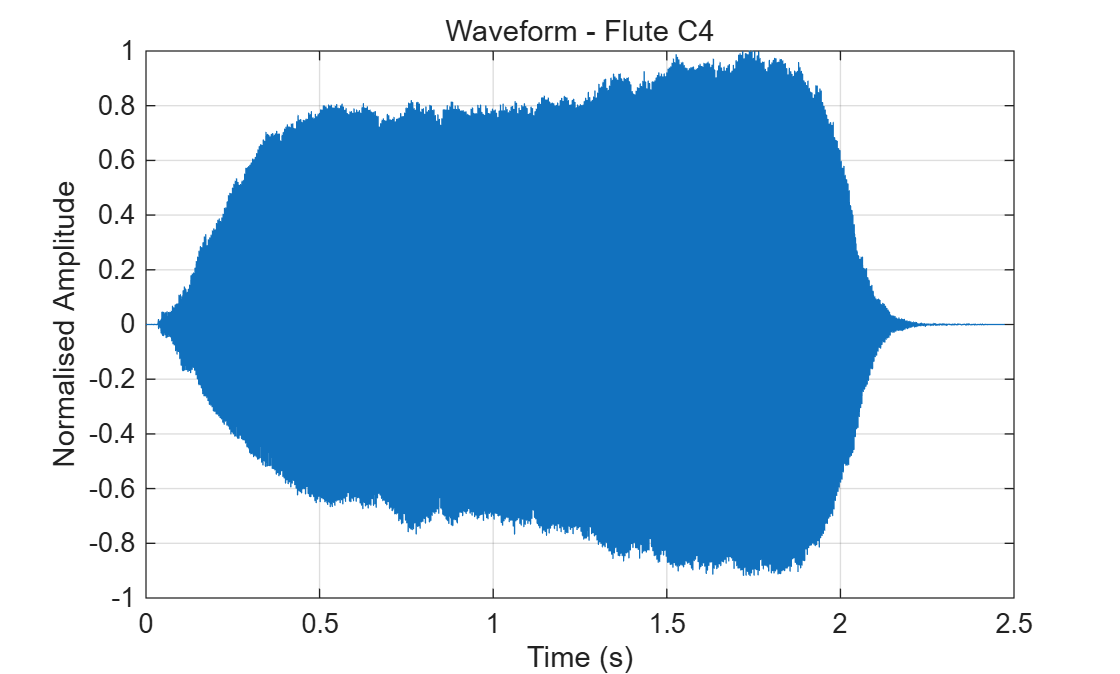

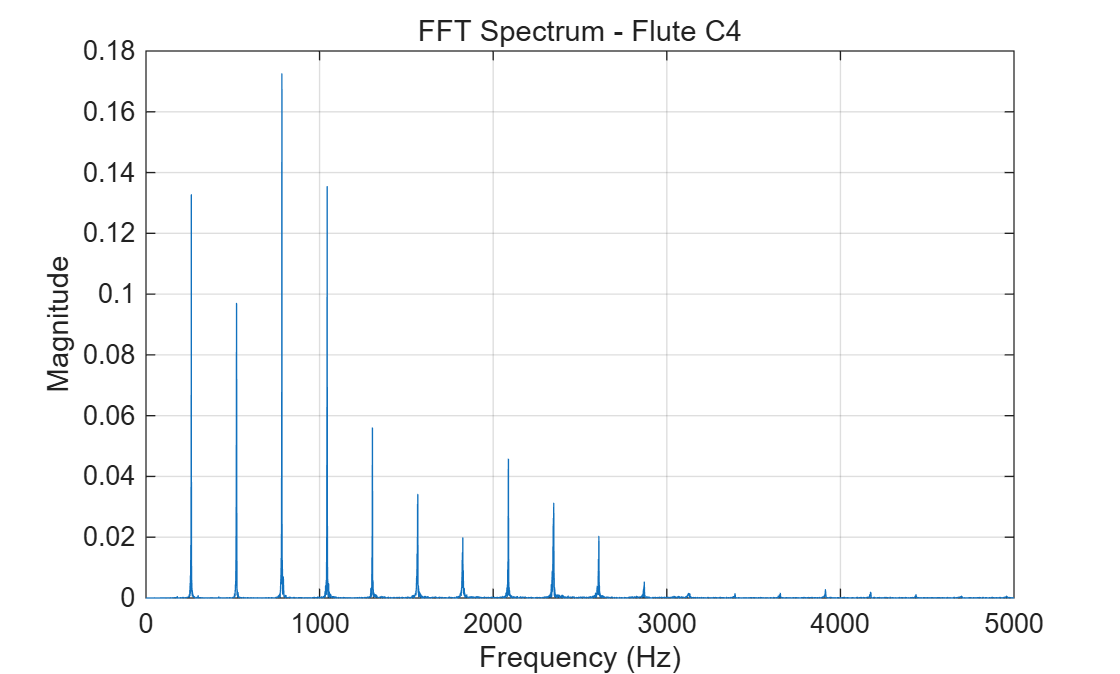

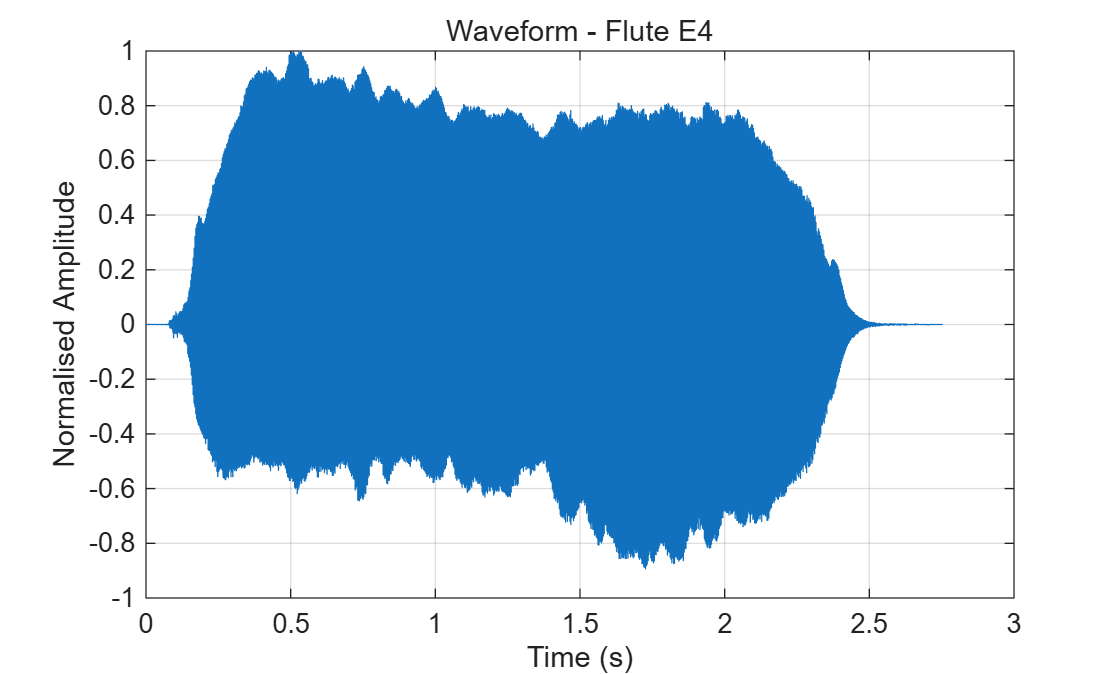

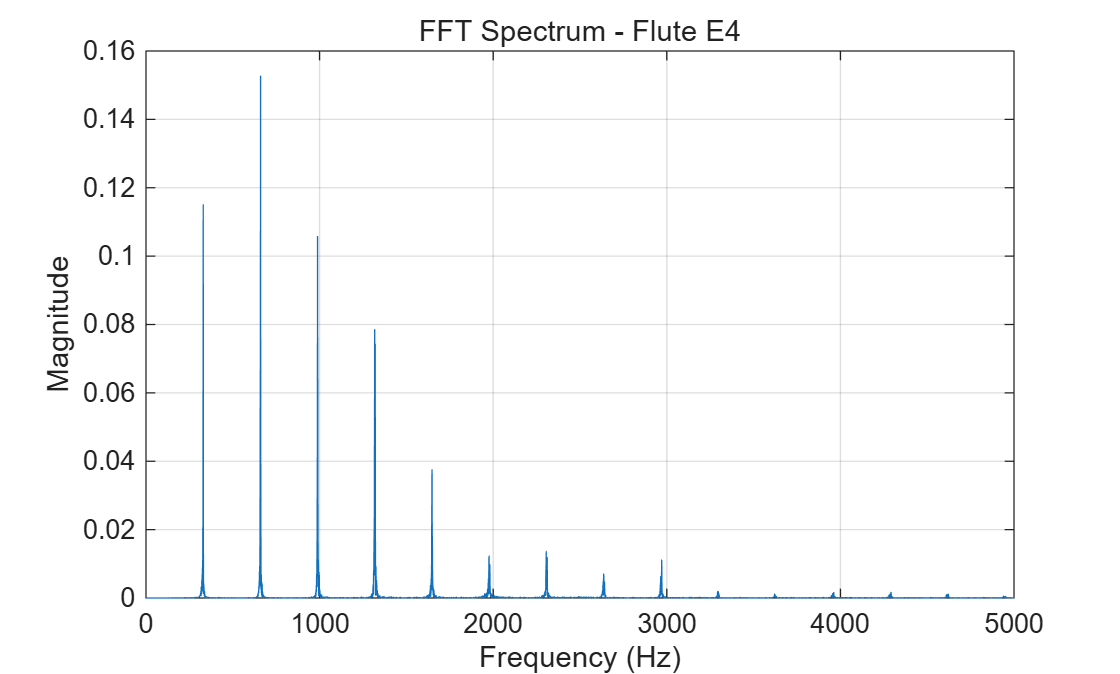

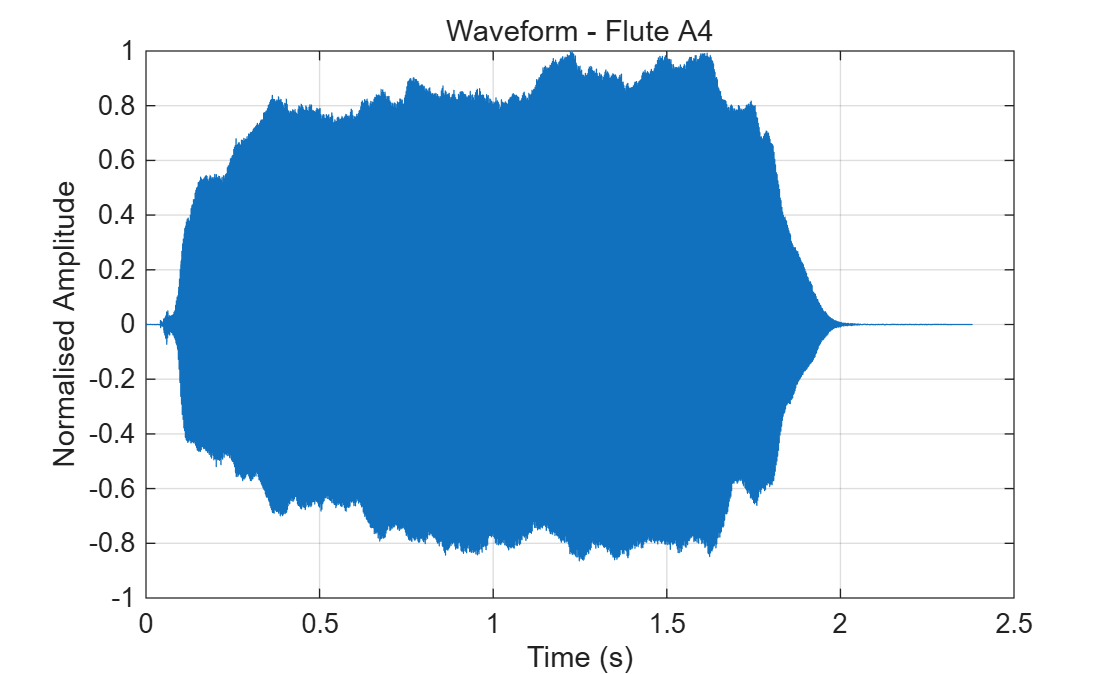

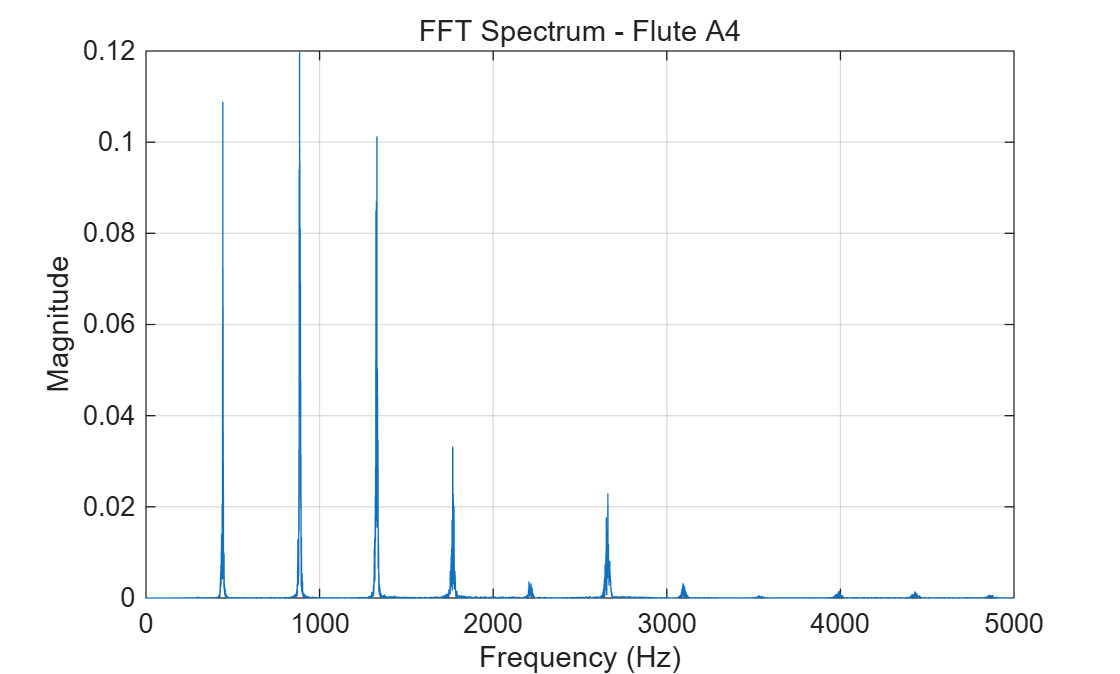

for i = 1:length(files)

    % Read audio
    [x, fs] = audioread(files{i});

    % Convert stereo to mono if necessary
    if size(x,2) == 2
        x = mean(x,2);
    end

    % Normalise amplitude
    x = x / max(abs(x));

    % Time axis
    t = (0:length(x)-1) / fs;

    % ---------- Waveform ----------
    figure;
    plot(t, x);
    xlabel('Time (s)');
    ylabel('Normalised Amplitude');
    title(['Waveform - Flute ', notes{i}]);
    grid on;

    % ---------- FFT Spectrum ----------
    N = length(x);

    X = fft(x);

    % Single-sided magnitude spectrum
    P2 = abs(X / N);
    P1 = P2(1:floor(N/2)+1);

    if length(P1) > 2
        P1(2:end-1) = 2 * P1(2:end-1);
    end

    f = fs * (0:floor(N/2)) / N;

    figure;
    plot(f, P1);
    xlim([0 5000]);
    xlabel('Frequency (Hz)');
    ylabel('Magnitude');
    title(['FFT Spectrum - Flute ', notes{i}]);
    grid on;

end

## **STFT Spectrogram Analys**

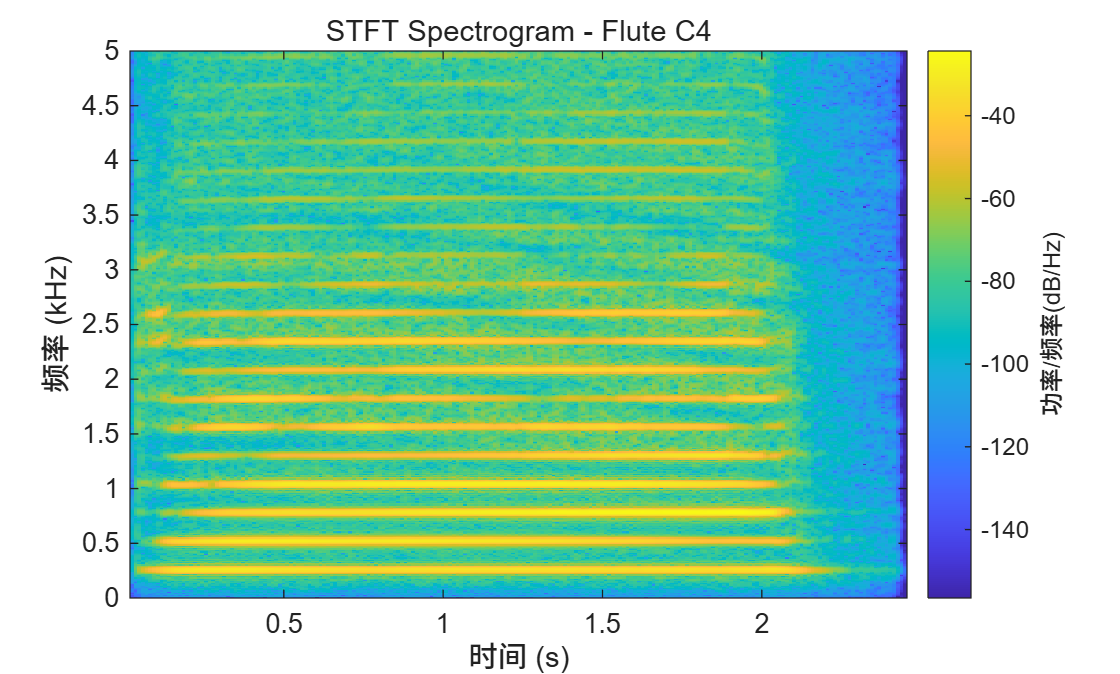

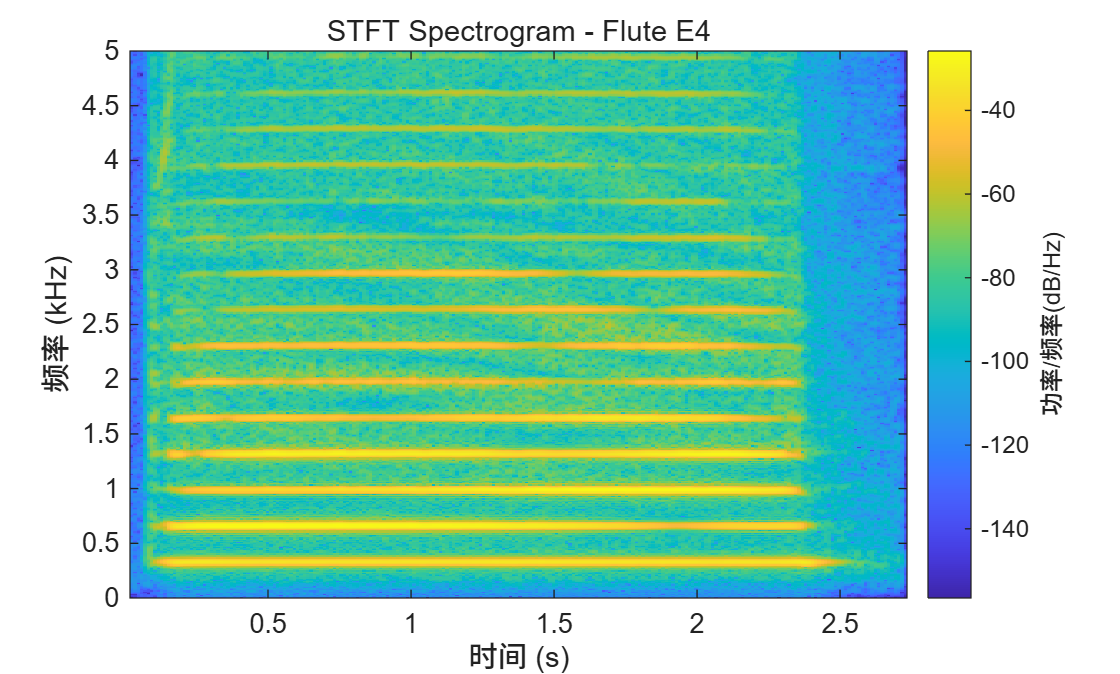

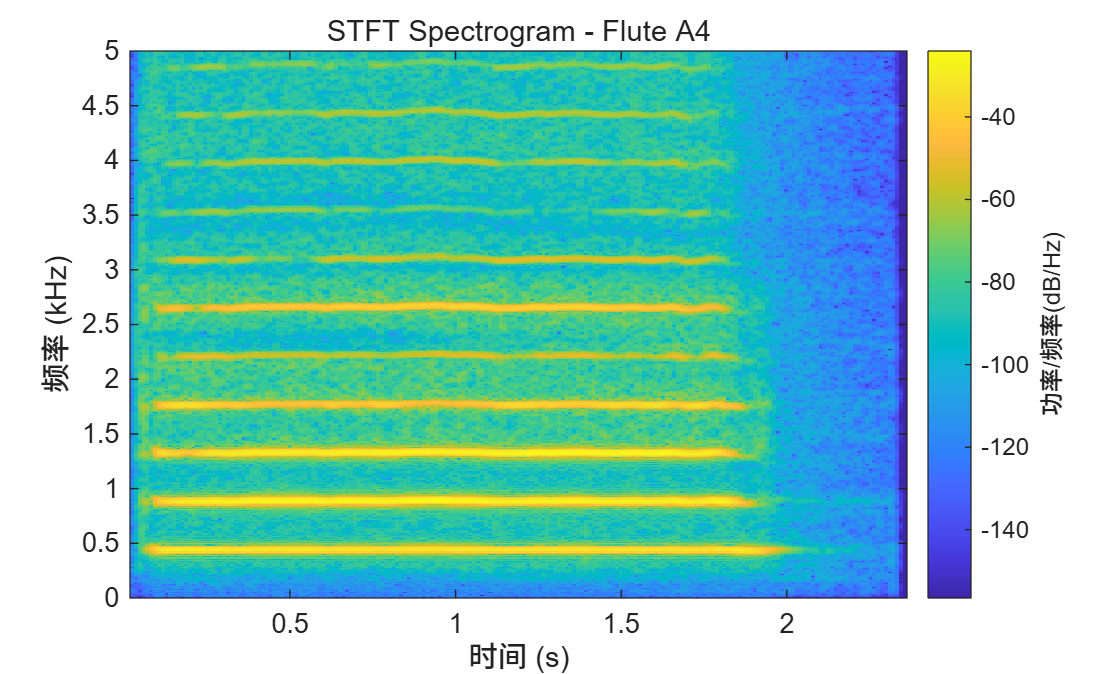

for i = 1:length(files)

    [x, fs] = audioread(files{i});

    if size(x,2) == 2
        x = mean(x,2);
    end

    x = x / max(abs(x));

    % STFT parameters
    windowLength = 2048;
    overlapLength = 1536;
    nfft = 4096;

    figure;
    spectrogram(x, hann(windowLength), overlapLength, nfft, fs, 'yaxis');
    ylim([0 5]);
    title(['STFT Spectrogram - Flute ', notes{i}]);

end

## **Harmonic Amplitude Extraction**

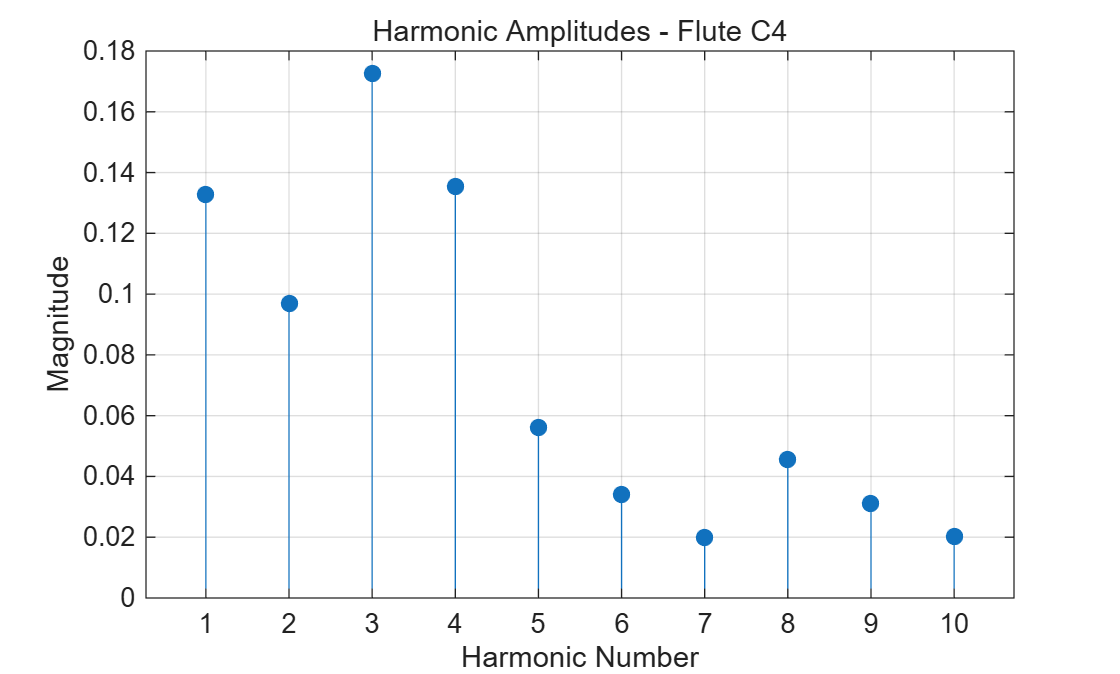


C4 Harmonics:


H1: 260.79 Hz, Amplitude = 0.1327
H2: 521.58 Hz, Amplitude = 0.0970
H3: 782.78 Hz, Amplitude = 0.1725
H4: 1043.57 Hz, Amplitude = 0.1354
H5: 1304.36 Hz, Amplitude = 0.0560
H6: 1565.56 Hz, Amplitude = 0.0341
H7: 1824.73 Hz, Amplitude = 0.0198
H8: 2087.54 Hz, Amplitude = 0.0457
H9: 2348.74 Hz, Amplitude = 0.0312
H10: 2608.72 Hz, Amplitude = 0.0202


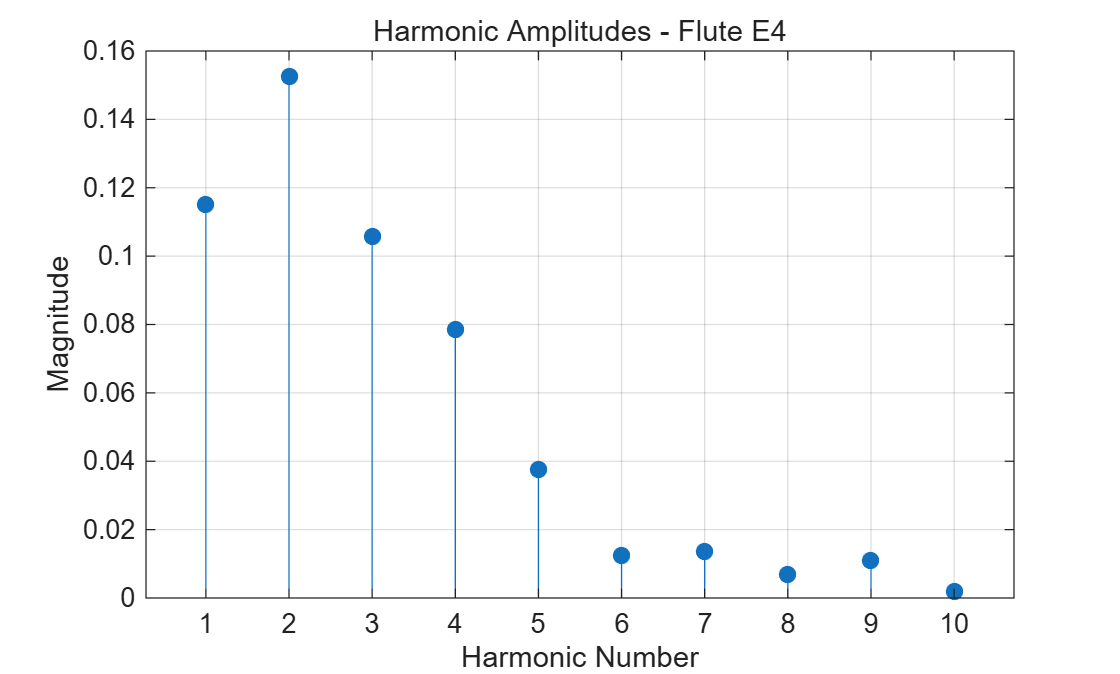


E4 Harmonics:


H1: 329.73 Hz, Amplitude = 0.1151
H2: 659.81 Hz, Amplitude = 0.1527
H3: 988.45 Hz, Amplitude = 0.1058
H4: 1317.45 Hz, Amplitude = 0.0785
H5: 1647.54 Hz, Amplitude = 0.0376
H6: 1976.53 Hz, Amplitude = 0.0123
H7: 2305.53 Hz, Amplitude = 0.0137
H8: 2636.71 Hz, Amplitude = 0.0070
H9: 2970.79 Hz, Amplitude = 0.0111
H10: 3293.62 Hz, Amplitude = 0.0020


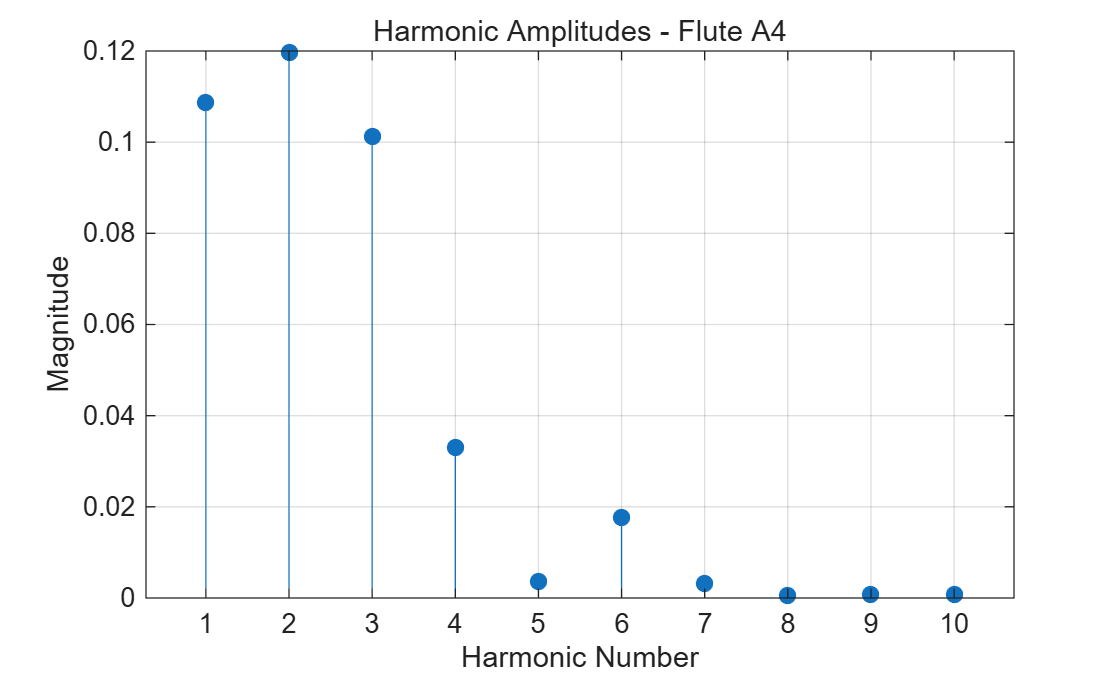


A4 Harmonics:


H1: 442.25 Hz, Amplitude = 0.1088
H2: 884.49 Hz, Amplitude = 0.1197
H3: 1330.10 Hz, Amplitude = 0.1012
H4: 1766.47 Hz, Amplitude = 0.0331
H5: 2205.78 Hz, Amplitude = 0.0035
H6: 2651.80 Hz, Amplitude = 0.0176
H7: 3094.05 Hz, Amplitude = 0.0032
H8: 3531.26 Hz, Amplitude = 0.0005
H9: 3976.45 Hz, Amplitude = 0.0008
H10: 4418.27 Hz, Amplitude = 0.0008


targetF0 = [261.63, 329.63, 440.00];
numHarmonics = 10;

for i = 1:length(files)

    [x, fs] = audioread(files{i});

    if size(x,2) == 2
        x = mean(x,2);
    end

    x = x / max(abs(x));

    % FFT
    N = length(x);
    X = fft(x);

    P2 = abs(X / N);
    P1 = P2(1:floor(N/2)+1);

    if length(P1) > 2
        P1(2:end-1) = 2 * P1(2:end-1);
    end

    f = fs * (0:floor(N/2)) / N;

    % Arrays for harmonic information
    harmonicFreqs = zeros(1,numHarmonics);
    harmonicAmps = zeros(1,numHarmonics);

    for k = 1:numHarmonics

        expectedFreq = k * targetF0(i);

        % Search within +/- 20 Hz
        searchRange = abs(f - expectedFreq) <= 20;

        localFreqs = f(searchRange);
        localAmps = P1(searchRange);

        [harmonicAmps(k), idx] = max(localAmps);
        harmonicFreqs(k) = localFreqs(idx);

    end

    % Plot harmonic amplitudes
    figure;
    stem(1:numHarmonics, harmonicAmps, 'filled');

    xlabel('Harmonic Number');
    ylabel('Magnitude');
    title(['Harmonic Amplitudes - Flute ', notes{i}]);
    grid on;

    % Print numerical results
    fprintf('\n%s Harmonics:\n', notes{i});

    for k = 1:numHarmonics
        fprintf('H%d: %.2f Hz, Amplitude = %.4f\n', ...
            k, harmonicFreqs(k), harmonicAmps(k));
    end

end

## ** Amplitude Envelope Extraction    **

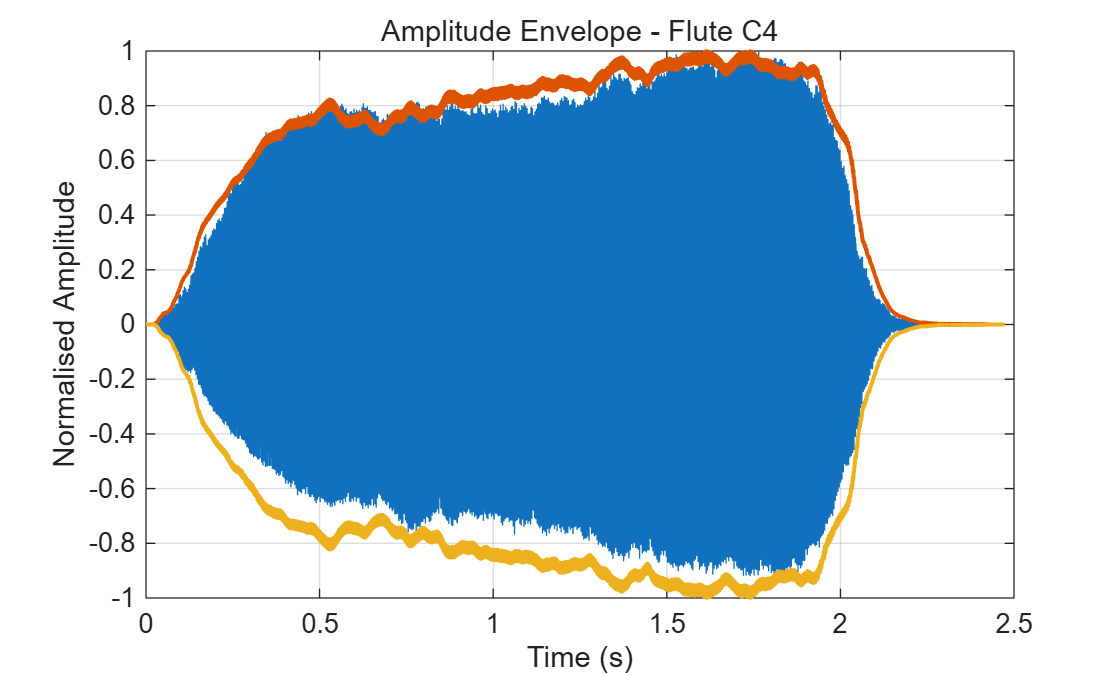

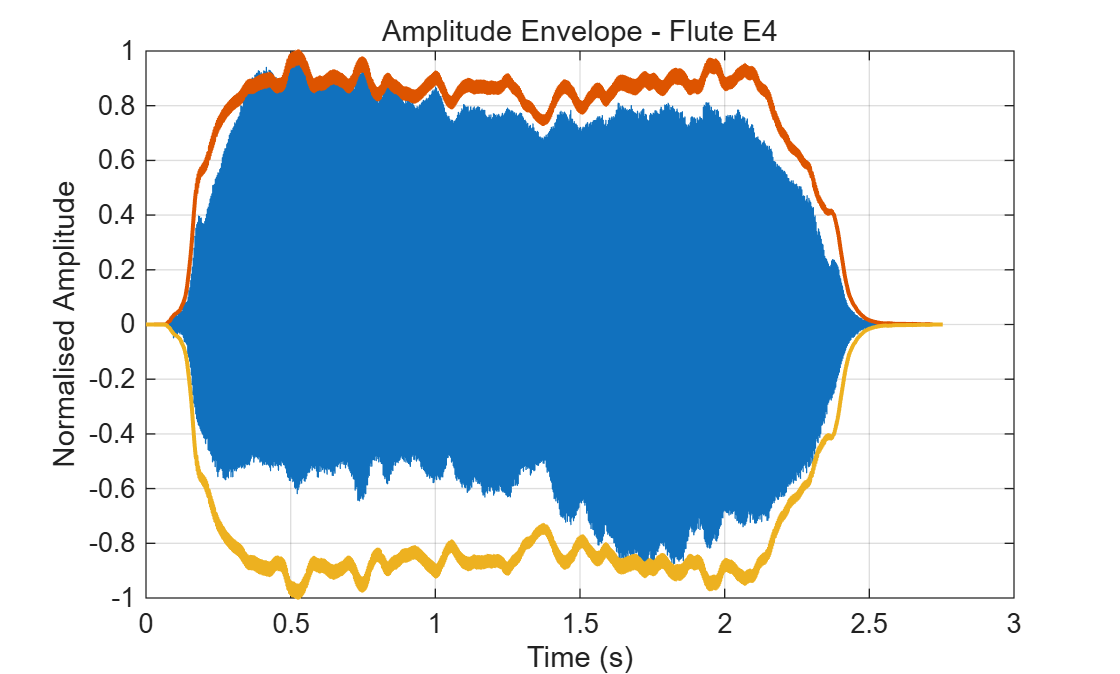

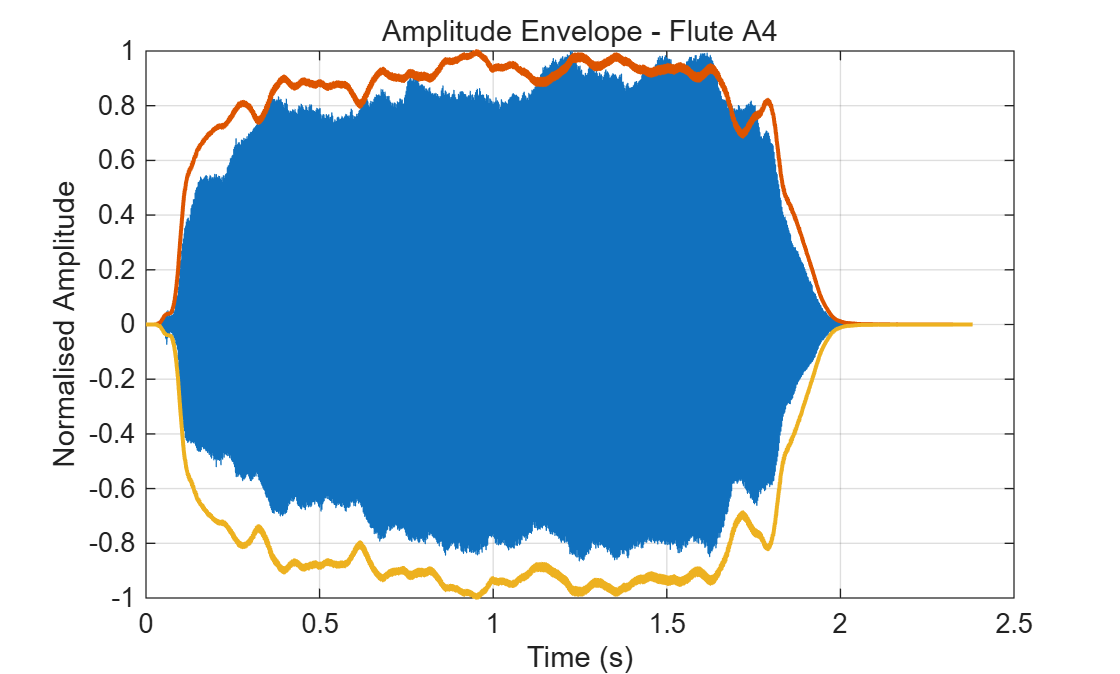

for i = 1:length(files)

    [x, fs] = audioread(files{i});

    if size(x,2) == 2
        x = mean(x,2);
    end

    x = x / max(abs(x));

    t = (0:length(x)-1) / fs;

    % RMS envelope
    windowSamples = round(0.02 * fs);
    envelope = sqrt(movmean(x.^2, windowSamples));

    envelope = envelope / max(envelope);

    figure;
    plot(t, x);
    hold on;
    plot(t, envelope, 'LineWidth', 1.5);
    plot(t, -envelope, 'LineWidth', 1.5);
    hold off;

    xlabel('Time (s)');
    ylabel('Normalised Amplitude');
    title(['Amplitude Envelope - Flute ', notes{i}]);
    grid on;

end

## **Basic Additive Synthesis**

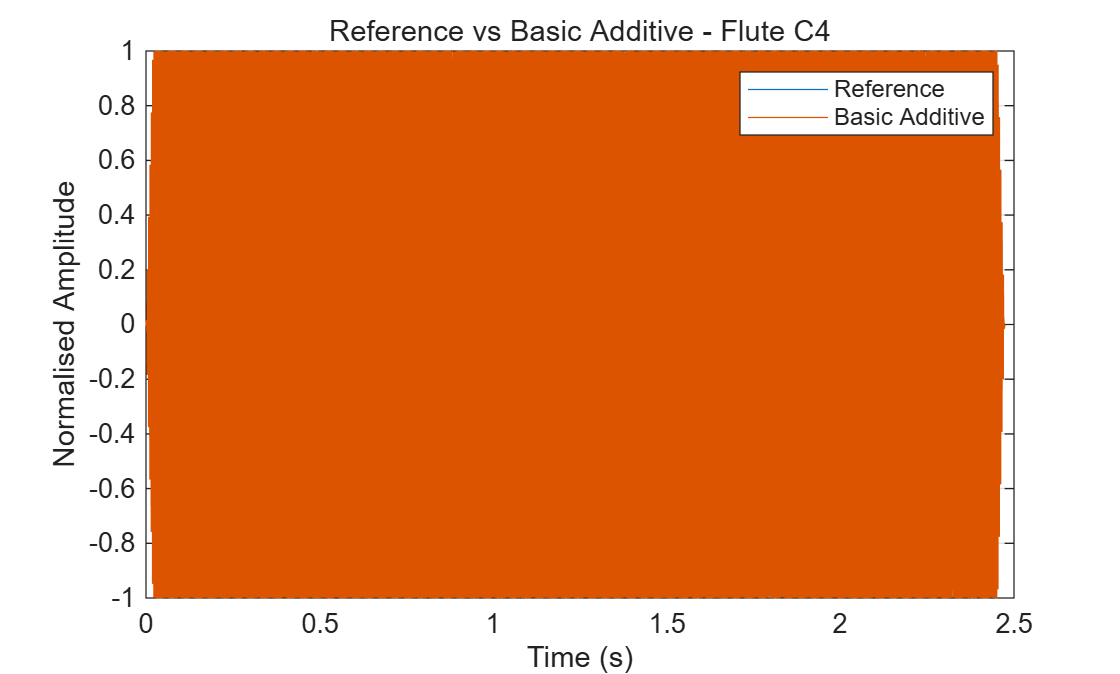

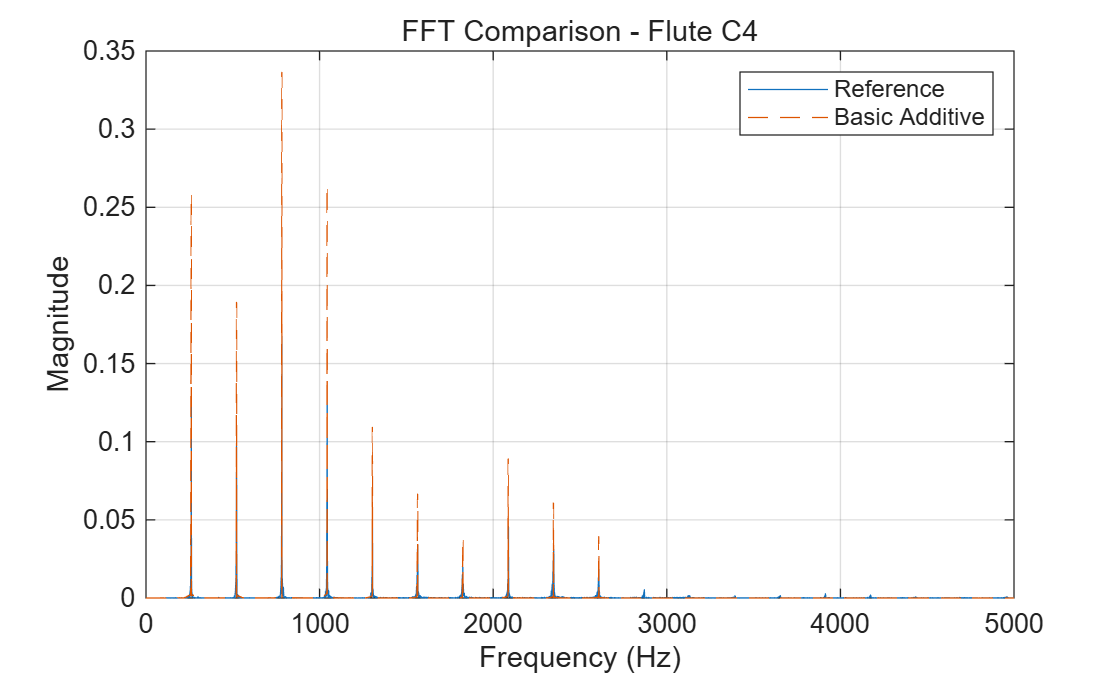

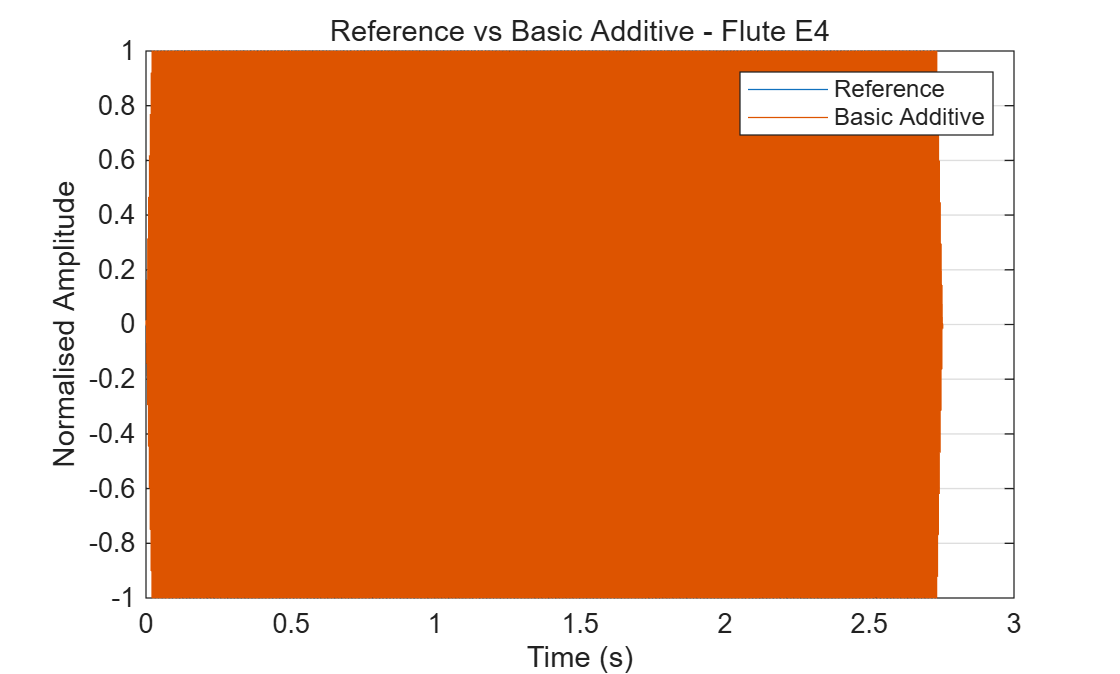

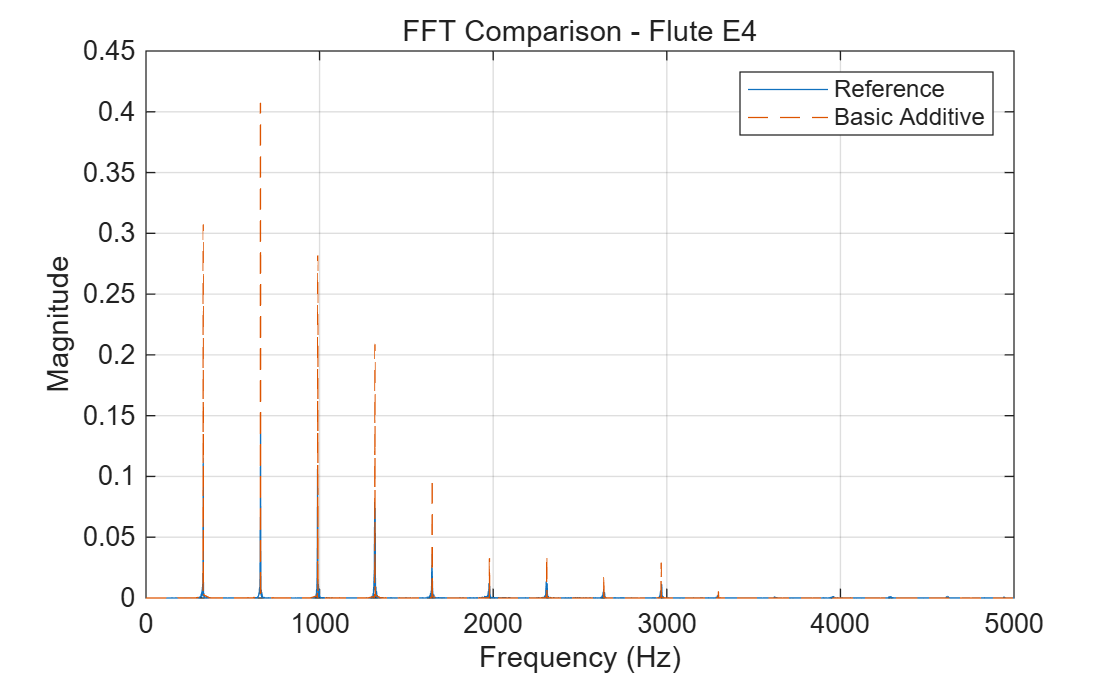

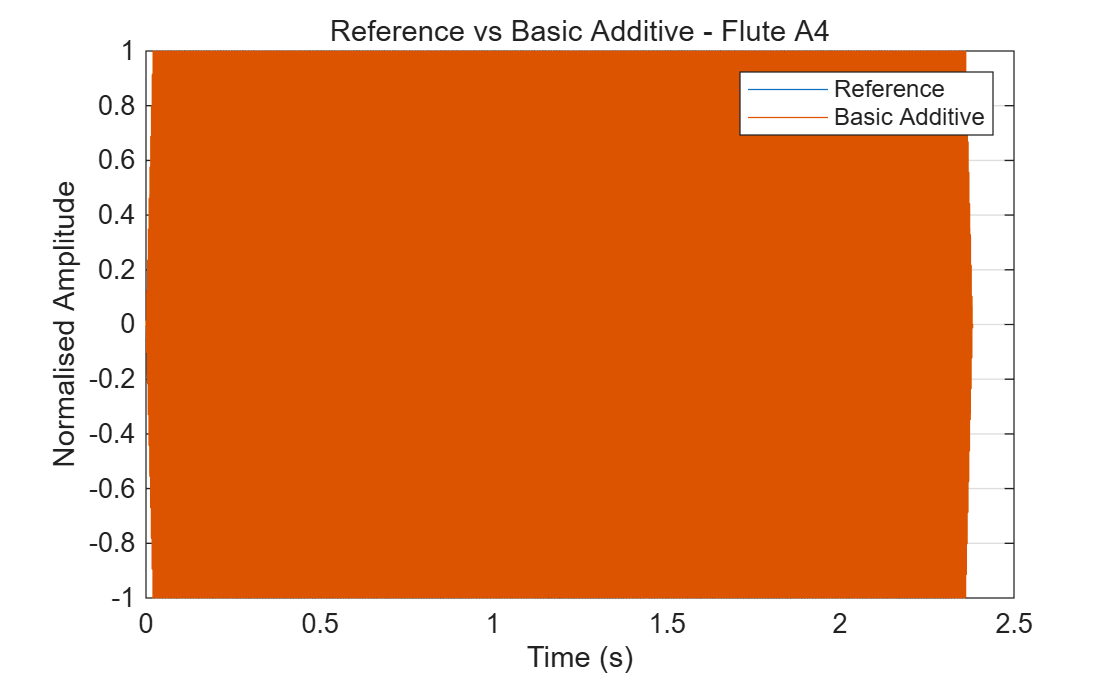

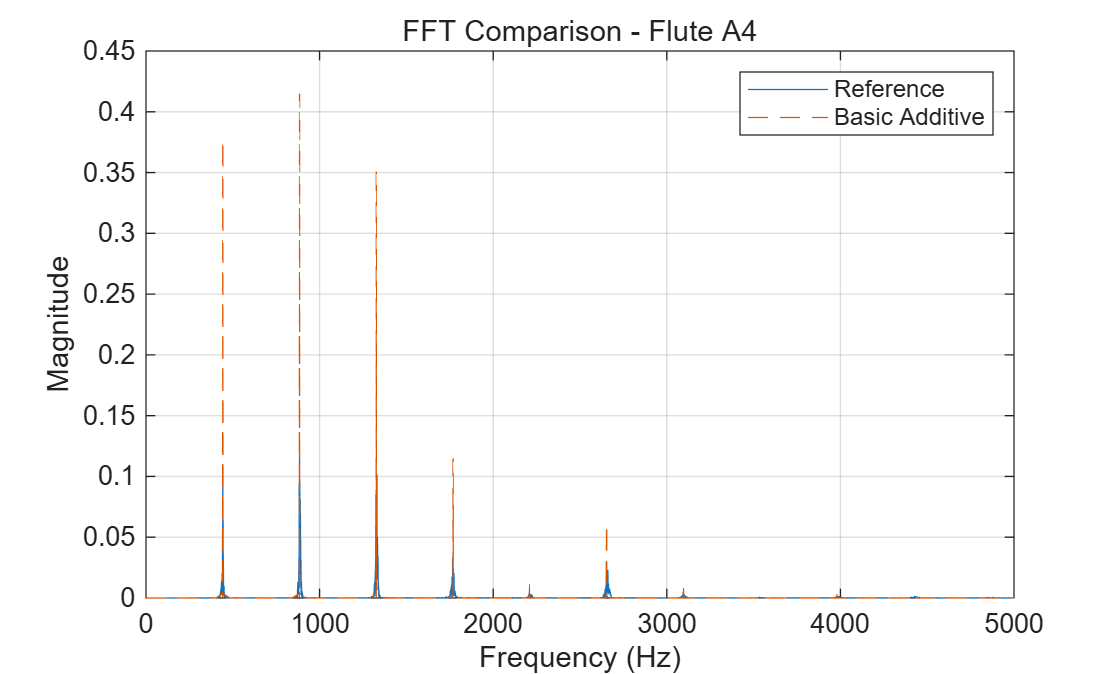


% Fundamental frequencies measured from the reference recordings
f0Values = [260.79, 329.73, 442.25];

% Harmonic amplitudes extracted from the reference recordings
harmonicAmpMatrix = [
    0.1327 0.0970 0.1725 0.1354 0.0560 0.0341 0.0198 0.0457 0.0312 0.0202;
    0.1151 0.1527 0.1058 0.0785 0.0376 0.0123 0.0137 0.0070 0.0111 0.0020;
    0.1088 0.1197 0.1012 0.0331 0.0035 0.0176 0.0032 0.0005 0.0008 0.0008
];

numHarmonics = 10;

for i = 1:length(files)

    % Read the reference audio to obtain sampling rate and duration
    [xRef, fs] = audioread(files{i});

    if size(xRef,2) == 2
        xRef = mean(xRef,2);
    end

    xRef = xRef / max(abs(xRef));

    duration = length(xRef) / fs;
    t = (0:length(xRef)-1)' / fs;

    % Fundamental frequency
    f0 = f0Values(i);

    % Harmonic amplitudes
    amps = harmonicAmpMatrix(i,:);

    % Normalise harmonic amplitudes
    amps = amps / max(amps);

    % Initialise synthesized signal
    xAdd = zeros(size(t));

    % Add the harmonic components
    for k = 1:numHarmonics
        xAdd = xAdd + amps(k) * sin(2*pi*k*f0*t);
    end

    % Normalise synthesized signal
    xAdd = xAdd / max(abs(xAdd));

    % Add a short fade-in and fade-out to avoid clicks
    fadeDuration = 0.02;
    fadeSamples = round(fadeDuration * fs);

    fadeIn = linspace(0,1,fadeSamples)';
    fadeOut = linspace(1,0,fadeSamples)';

    xAdd(1:fadeSamples) = xAdd(1:fadeSamples) .* fadeIn;
    xAdd(end-fadeSamples+1:end) = ...
        xAdd(end-fadeSamples+1:end) .* fadeOut;

    % ---------- Waveform comparison ----------
    figure;

    plot(t, xRef);
    hold on;
    plot(t, xAdd);
    hold off;

    xlabel('Time (s)');
    ylabel('Normalised Amplitude');
    title(['Reference vs Basic Additive - Flute ', notes{i}]);
    legend('Reference', 'Basic Additive');
    grid on;

    % ---------- FFT comparison ----------
    N = length(xRef);

    Xref = fft(xRef);
    Xadd = fft(xAdd);

    Pref = abs(Xref/N);
    Padd = abs(Xadd/N);

    Pref = Pref(1:floor(N/2)+1);
    Padd = Padd(1:floor(N/2)+1);

    if length(Pref) > 2
        Pref(2:end-1) = 2 * Pref(2:end-1);
        Padd(2:end-1) = 2 * Padd(2:end-1);
    end

    f = fs * (0:floor(N/2)) / N;

    figure;

    plot(f, Pref);
    hold on;
    plot(f, Padd, '--');
    hold off;

    xlim([0 5000]);
    xlabel('Frequency (Hz)');
    ylabel('Magnitude');
    title(['FFT Comparison - Flute ', notes{i}]);
    legend('Reference', 'Basic Additive');
    grid on;

    % ---------- Save synthesized audio ----------
    outputFile = fullfile(projectRoot, ...
        'audio_output', ...
        ['Flute_', notes{i}, '_Basic_Additive.wav']);

    audiowrite(outputFile, xAdd, fs);

end

## Envelope-Based Additive Synthesis

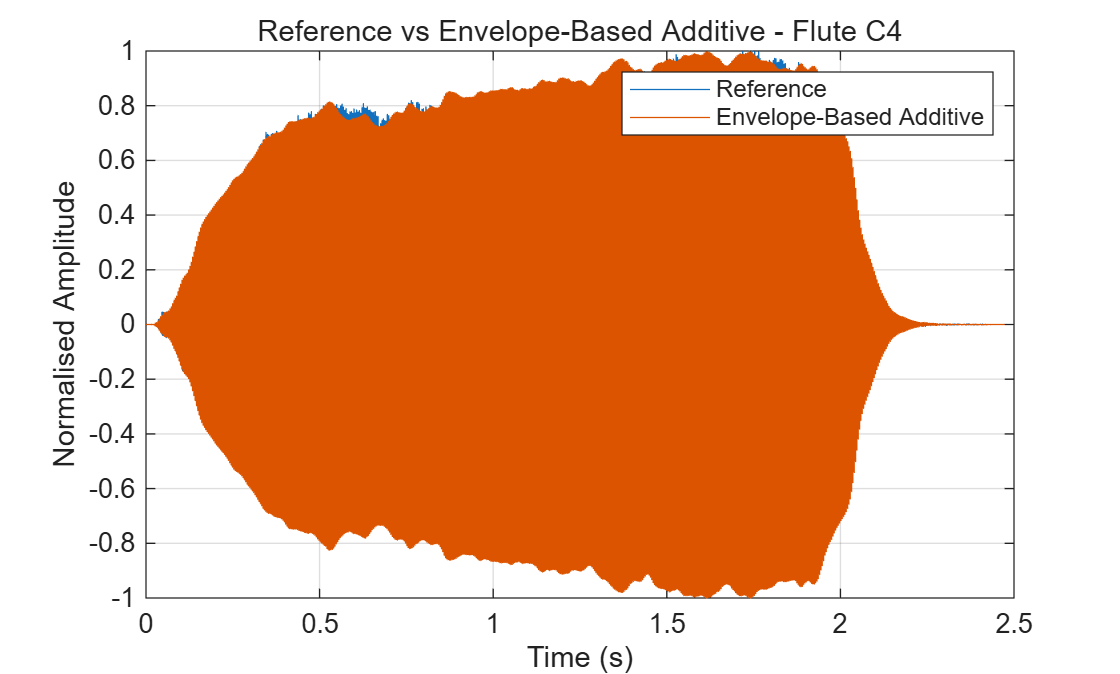

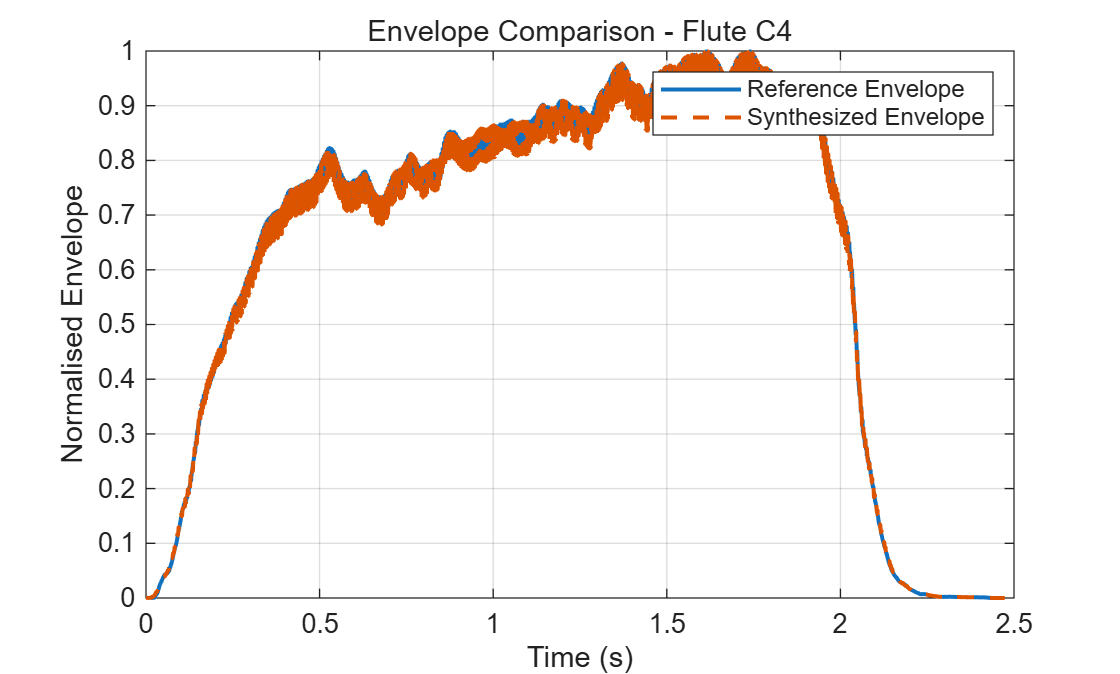

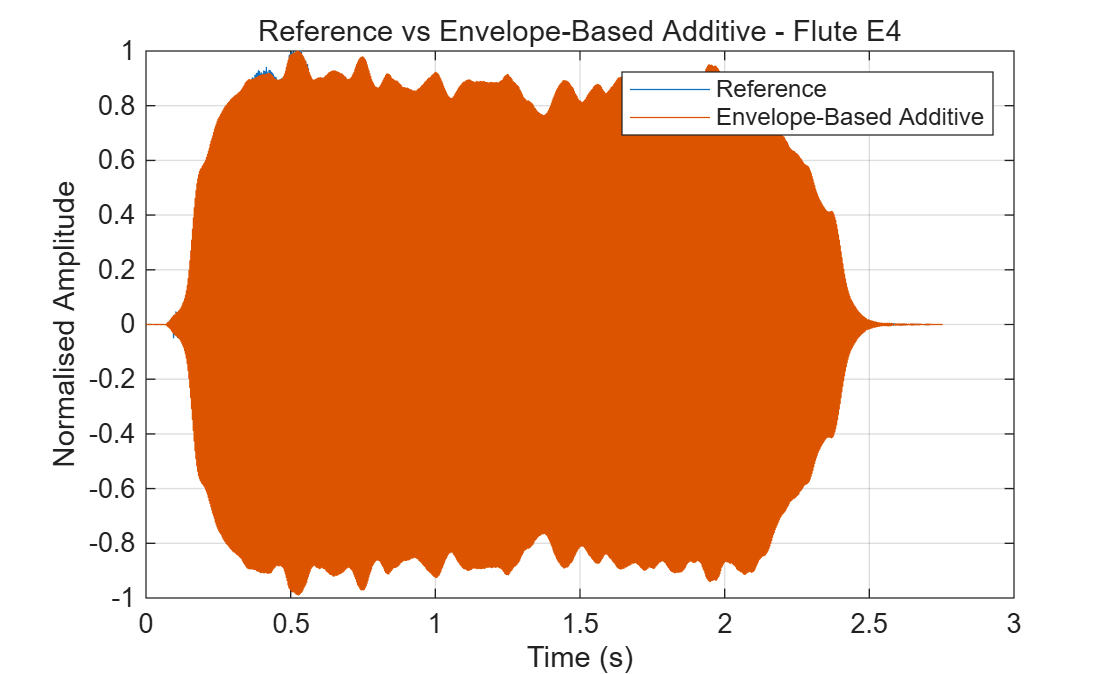

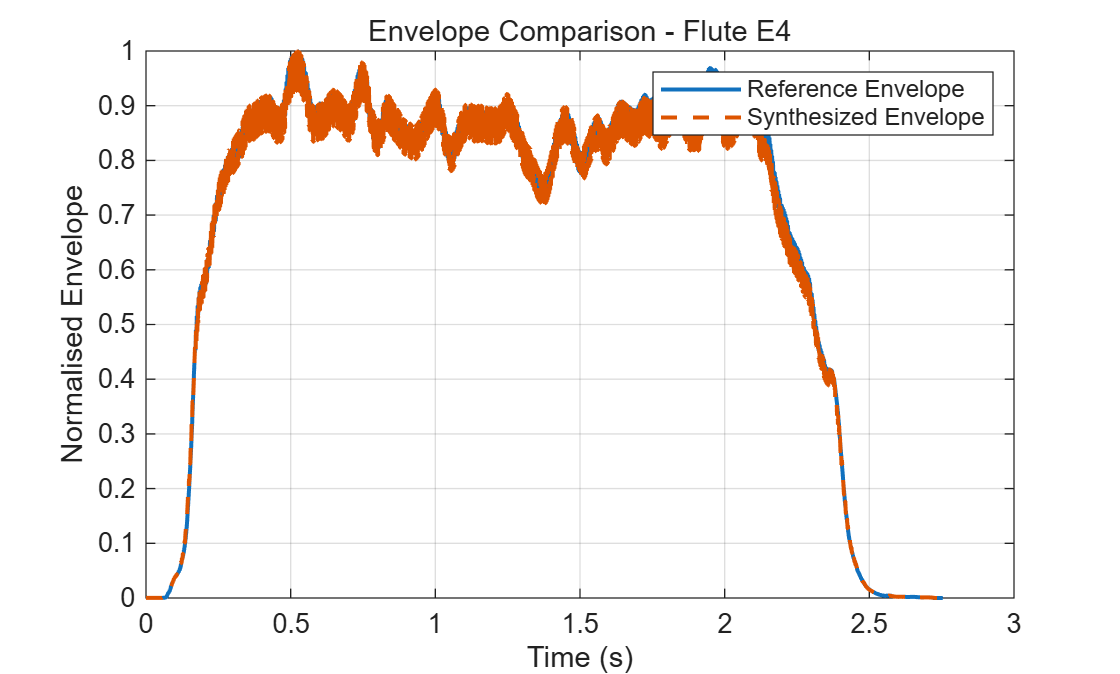

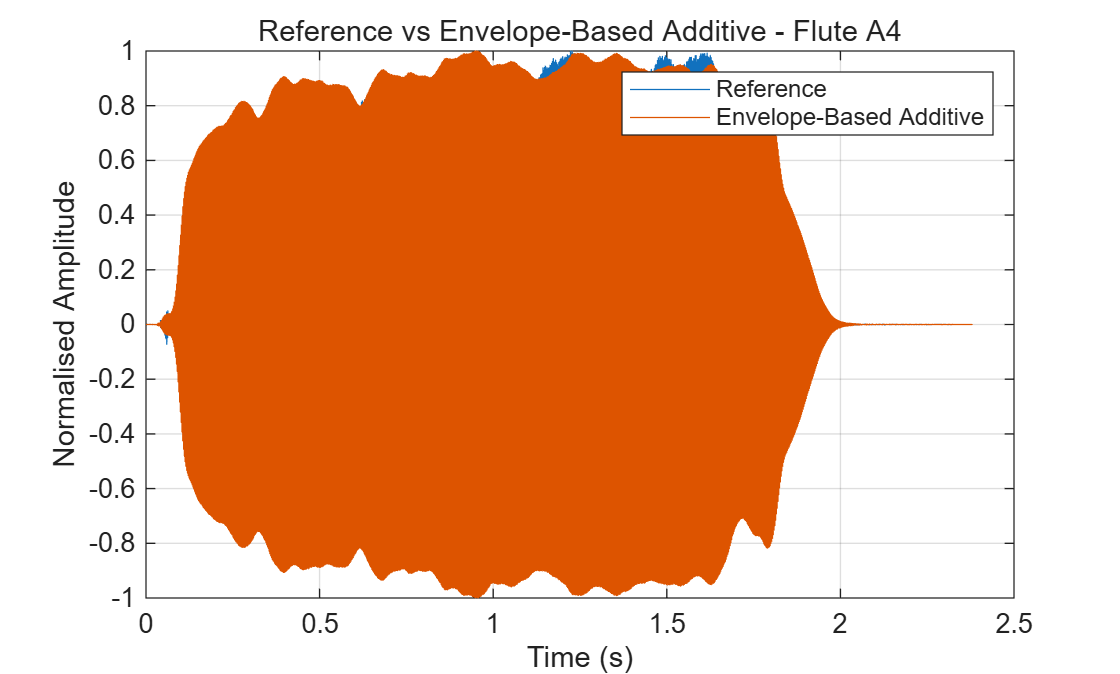

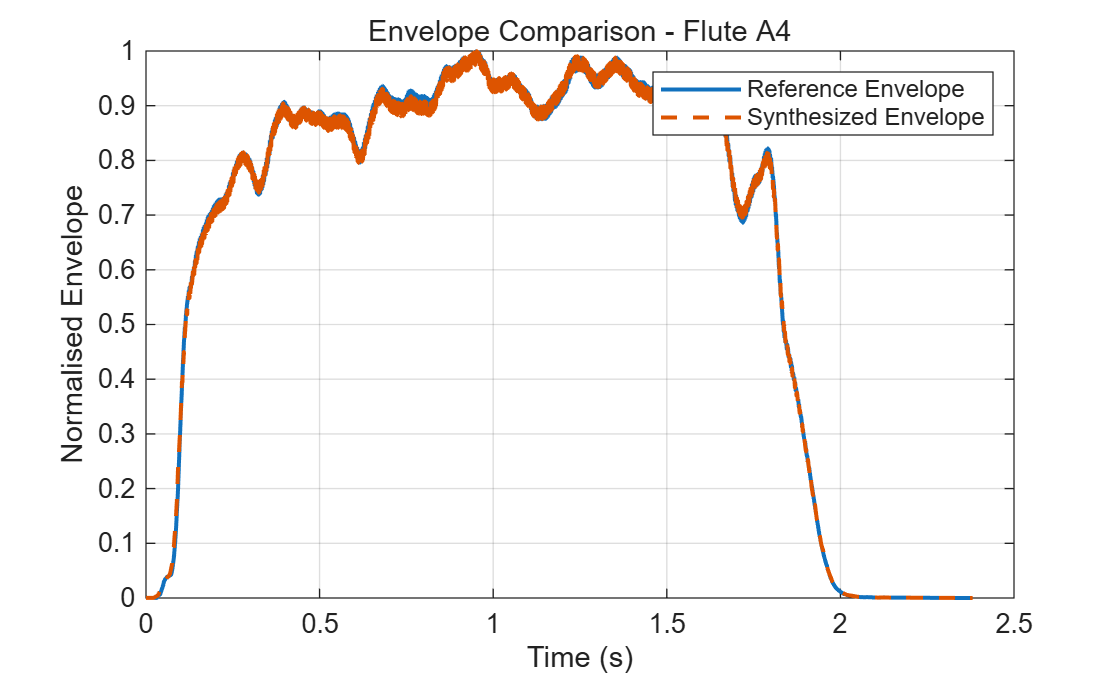

f0Values = [260.79, 329.73, 442.25];

harmonicAmpMatrix = [
    0.1327 0.0970 0.1725 0.1354 0.0560 0.0341 0.0198 0.0457 0.0312 0.0202;
    0.1151 0.1527 0.1058 0.0785 0.0376 0.0123 0.0137 0.0070 0.0111 0.0020;
    0.1088 0.1197 0.1012 0.0331 0.0035 0.0176 0.0032 0.0005 0.0008 0.0008
];

numHarmonics = 10;

for i = 1:length(files)

    % Read reference audio
    [xRef, fs] = audioread(files{i});

    if size(xRef,2) == 2
        xRef = mean(xRef,2);
    end

    xRef = xRef / max(abs(xRef));

    t = (0:length(xRef)-1)' / fs;

    % ---------- Extract amplitude envelope ----------
    windowSamples = round(0.02 * fs);

    ampEnvelope = sqrt(movmean(xRef.^2, windowSamples));

    % Normalise envelope
    ampEnvelope = ampEnvelope / max(ampEnvelope);

    % ---------- Generate basic harmonic signal ----------
    f0 = f0Values(i);

    amps = harmonicAmpMatrix(i,:);
    amps = amps / max(amps);

    xAdd = zeros(size(t));

    for k = 1:numHarmonics

        xAdd = xAdd + ...
            amps(k) * sin(2*pi*k*f0*t);

    end

    % ---------- Apply reference amplitude envelope ----------
    xAddEnv = xAdd .* ampEnvelope;

    % Normalise final signal
    xAddEnv = xAddEnv / max(abs(xAddEnv));

    % ---------- Waveform comparison ----------
    figure;

    plot(t, xRef);
    hold on;
    plot(t, xAddEnv);
    hold off;

    xlabel('Time (s)');
    ylabel('Normalised Amplitude');

    title(['Reference vs Envelope-Based Additive - Flute ', ...
        notes{i}]);

    legend('Reference', 'Envelope-Based Additive');
    grid on;

    % ---------- Envelope comparison ----------
    synthEnvelope = sqrt( ...
        movmean(xAddEnv.^2, windowSamples));

    synthEnvelope = synthEnvelope / max(synthEnvelope);

    figure;

    plot(t, ampEnvelope, 'LineWidth', 1.5);
    hold on;
    plot(t, synthEnvelope, '--', 'LineWidth', 1.5);
    hold off;

    xlabel('Time (s)');
    ylabel('Normalised Envelope');

    title(['Envelope Comparison - Flute ', notes{i}]);

    legend('Reference Envelope', ...
        'Synthesized Envelope');

    grid on;

    % ---------- Save synthesized audio ----------
    outputFile = fullfile( ...
        projectRoot, ...
        'audio_output', ...
        ['Flute_', notes{i}, ...
        '_Envelope_Additive.wav']);

    audiowrite(outputFile, xAddEnv, fs);

end

## **Time-Varying Harmonic Additive Synthesis**

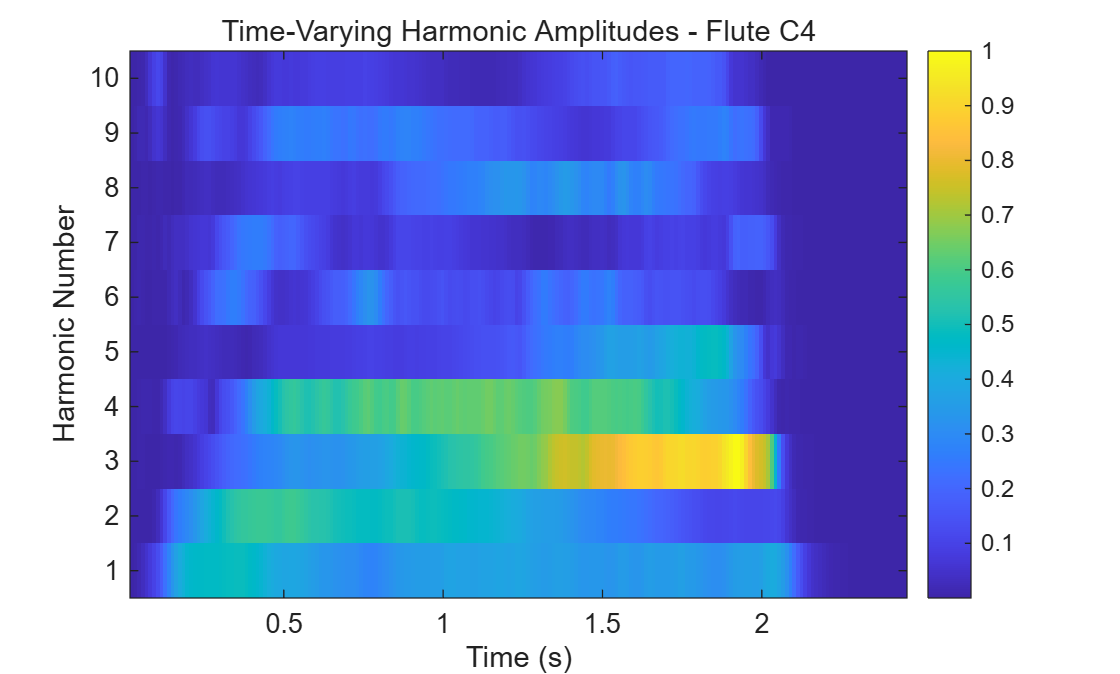

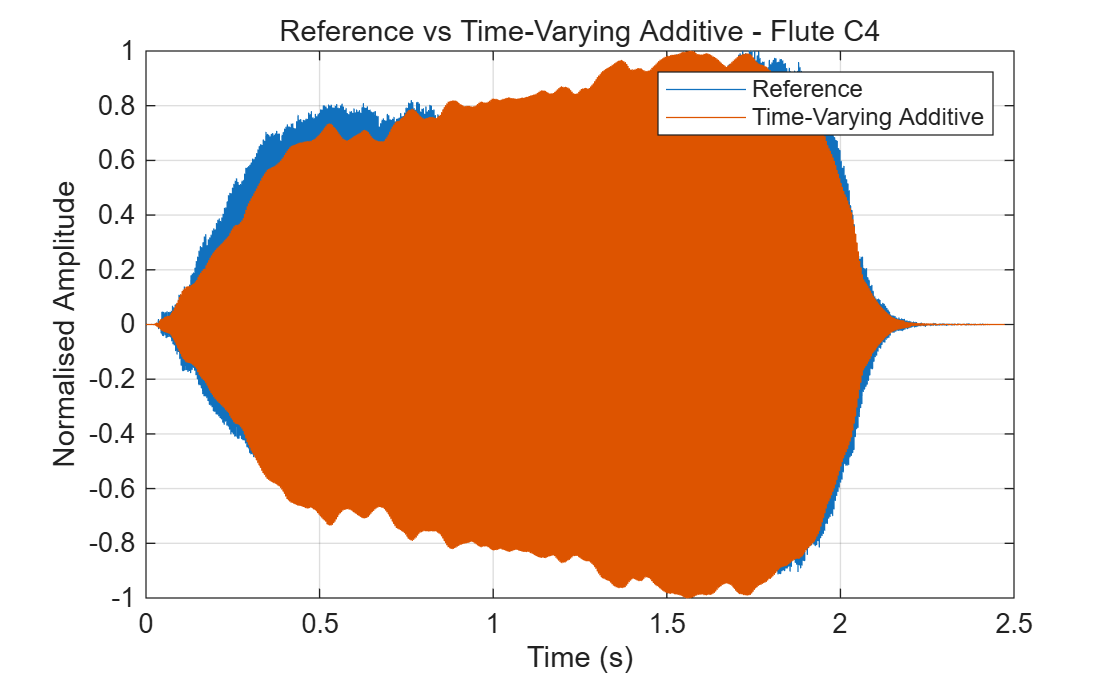

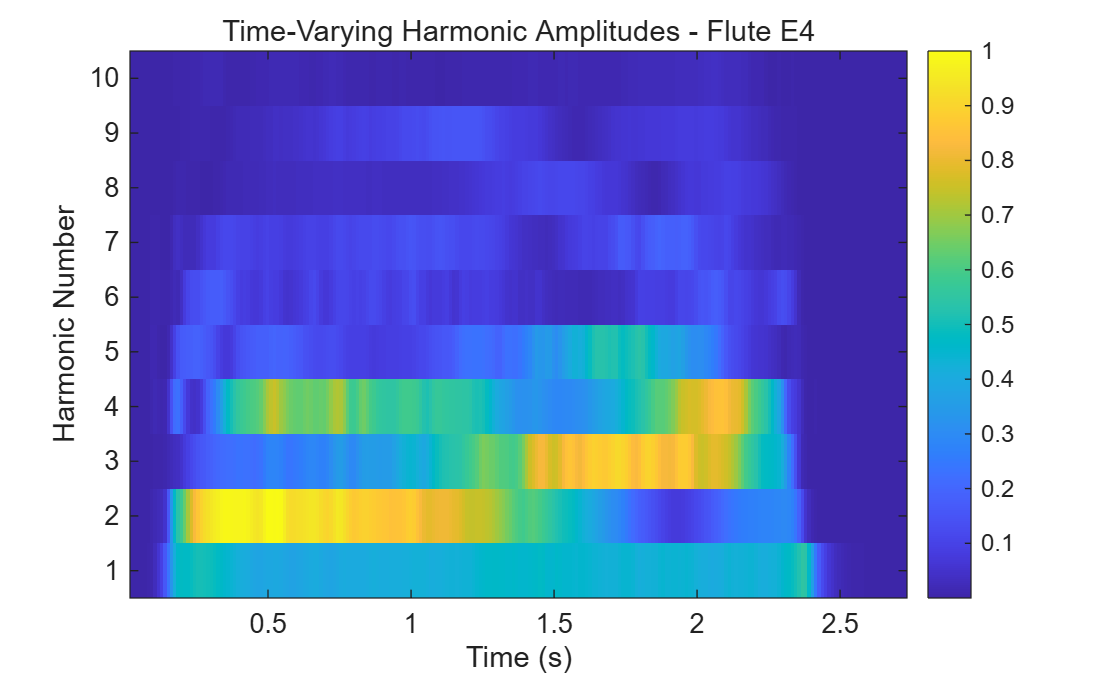

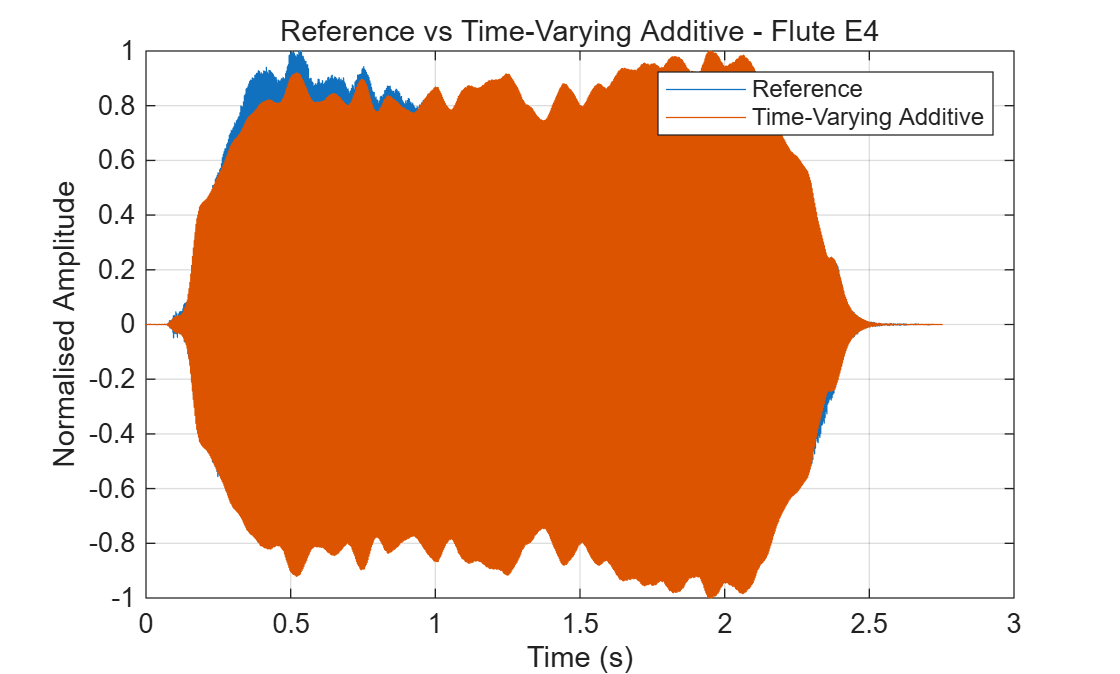

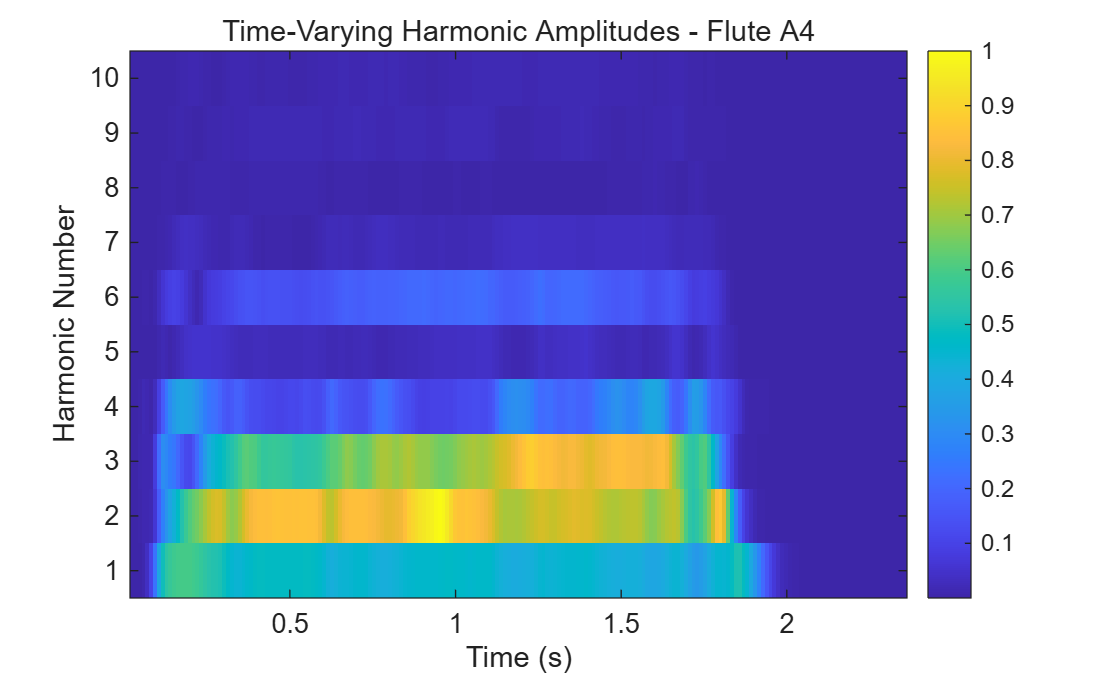

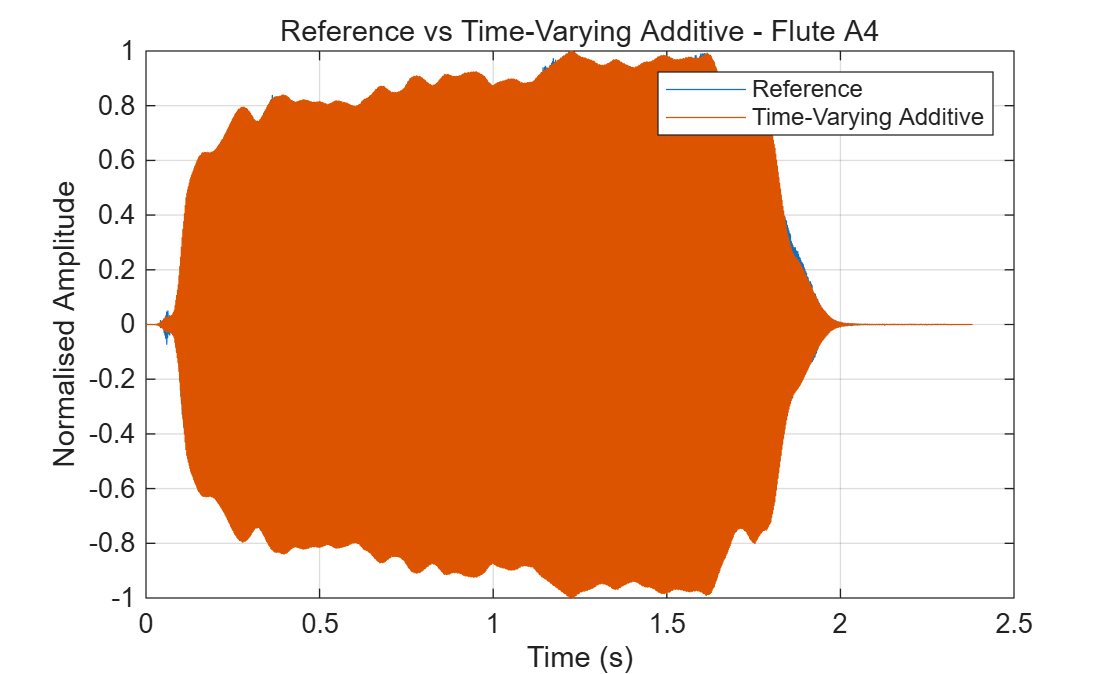

f0Values = [260.79, 329.73, 442.25];
numHarmonics = 10;

for i = 1:length(files)

    % Read reference audio
    [xRef, fs] = audioread(files{i});

    if size(xRef,2) == 2
        xRef = mean(xRef,2);
    end

    xRef = xRef / max(abs(xRef));

    % ---------- STFT ----------
    windowLength = 2048;
    overlapLength = 1536;
    nfft = 4096;

    [S,F,T] = spectrogram( ...
        xRef, ...
        hann(windowLength), ...
        overlapLength, ...
        nfft, ...
        fs);

    magnitudeSTFT = abs(S);

    f0 = f0Values(i);

    % Store time-varying harmonic amplitudes
    harmonicTracks = zeros(numHarmonics, length(T));

    % ---------- Extract harmonic tracks ----------
    for k = 1:numHarmonics

        expectedFreq = k * f0;

        % Search within +/- 20 Hz
        searchBins = abs(F - expectedFreq) <= 20;

        localMag = magnitudeSTFT(searchBins, :);

        % Maximum magnitude around each expected harmonic
        harmonicTracks(k,:) = max(localMag, [], 1);

    end

    % Normalise all harmonic tracks
    harmonicTracks = harmonicTracks / max(harmonicTracks(:));

    % ---------- Plot harmonic evolution ----------
    figure;

    imagesc(T, 1:numHarmonics, harmonicTracks);
    axis xy;

    xlabel('Time (s)');
    ylabel('Harmonic Number');

    title(['Time-Varying Harmonic Amplitudes - Flute ', notes{i}]);

    colorbar;

    % ---------- Interpolate harmonic tracks to sample level ----------
    t = (0:length(xRef)-1)' / fs;

    harmonicTracksSample = zeros(numHarmonics, length(t));

    for k = 1:numHarmonics

        harmonicTracksSample(k,:) = interp1( ...
            T, ...
            harmonicTracks(k,:), ...
            t, ...
            'linear', ...
            0);

    end

    % ---------- Additive synthesis ----------
    xTVAdd = zeros(size(t));

    for k = 1:numHarmonics

        amplitudeTrack = harmonicTracksSample(k,:)';

        xTVAdd = xTVAdd + ...
            amplitudeTrack .* ...
            sin(2*pi*k*f0*t);

    end

    % Normalise
    xTVAdd = xTVAdd / max(abs(xTVAdd));

    % ---------- Waveform comparison ----------
    figure;

    plot(t, xRef);
    hold on;
    plot(t, xTVAdd);
    hold off;

    xlabel('Time (s)');
    ylabel('Normalised Amplitude');

    title(['Reference vs Time-Varying Additive - Flute ', ...
        notes{i}]);

    legend('Reference', 'Time-Varying Additive');
    grid on;

    % ---------- Save audio ----------
    outputFile = fullfile( ...
        projectRoot, ...
        'audio_output', ...
        ['Flute_', notes{i}, ...
        '_TimeVarying_Additive.wav']);

    audiowrite(outputFile, xTVAdd, fs);

end

## ** Basic Two-Operator FM Synthesis**

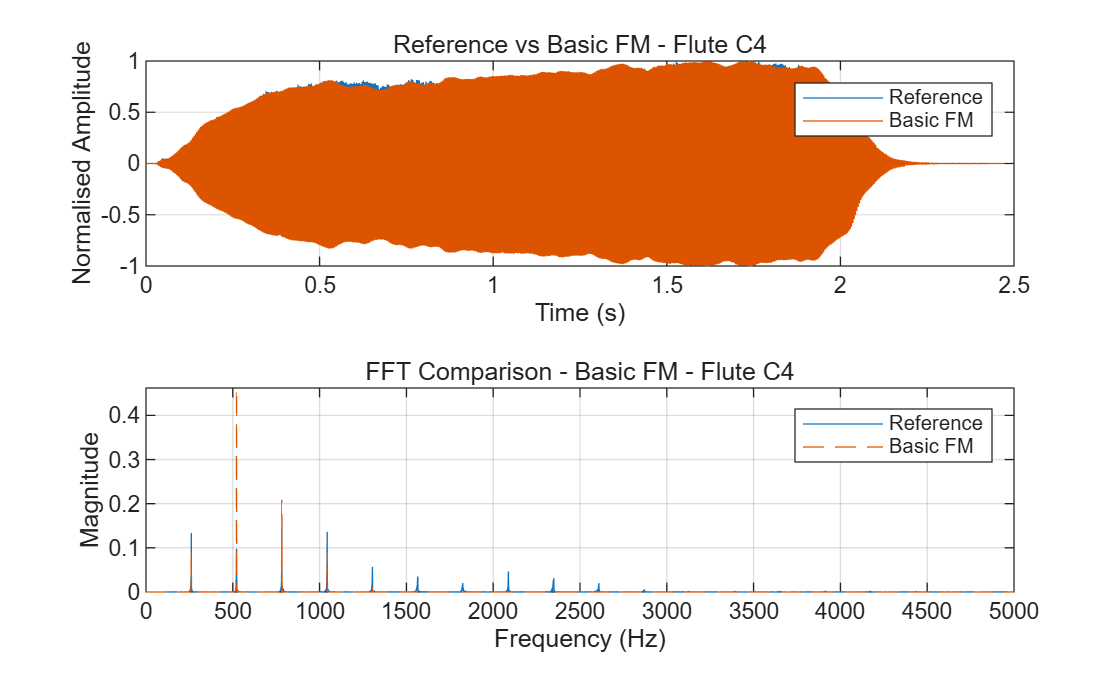


C4 Basic FM Parameters:


Fundamental Frequency = 260.79 Hz


Carrier Frequency = 260.79 Hz


Modulator Frequency = 260.79 Hz


Modulation Index = 2.00


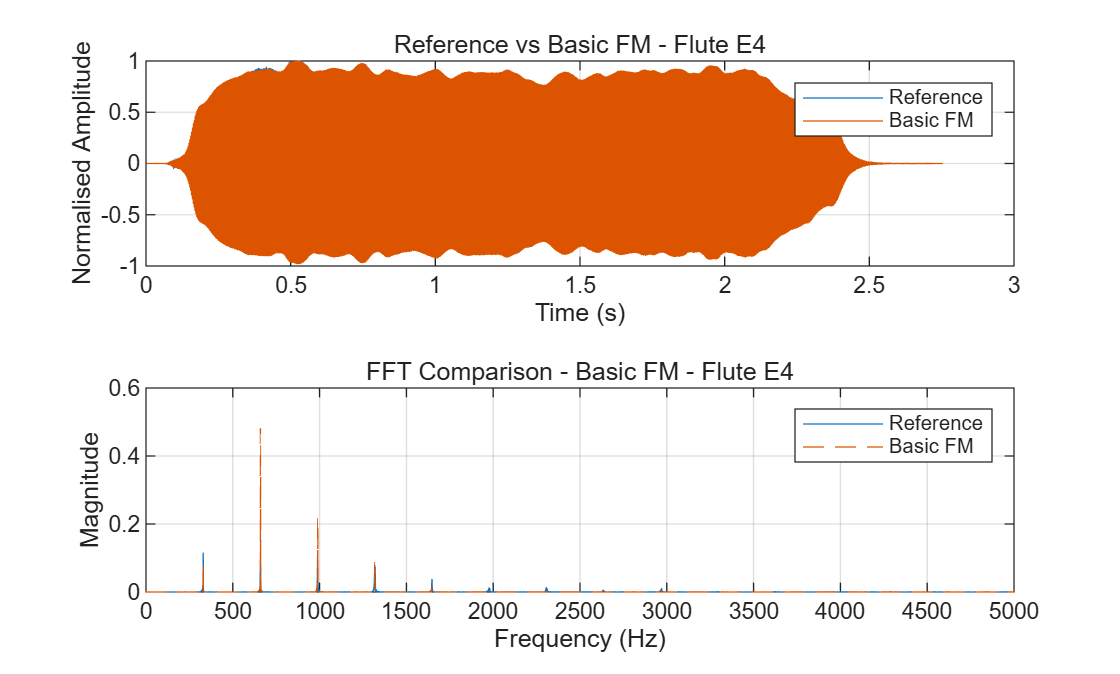


E4 Basic FM Parameters:


Fundamental Frequency = 329.73 Hz


Carrier Frequency = 329.73 Hz


Modulator Frequency = 329.73 Hz


Modulation Index = 2.00


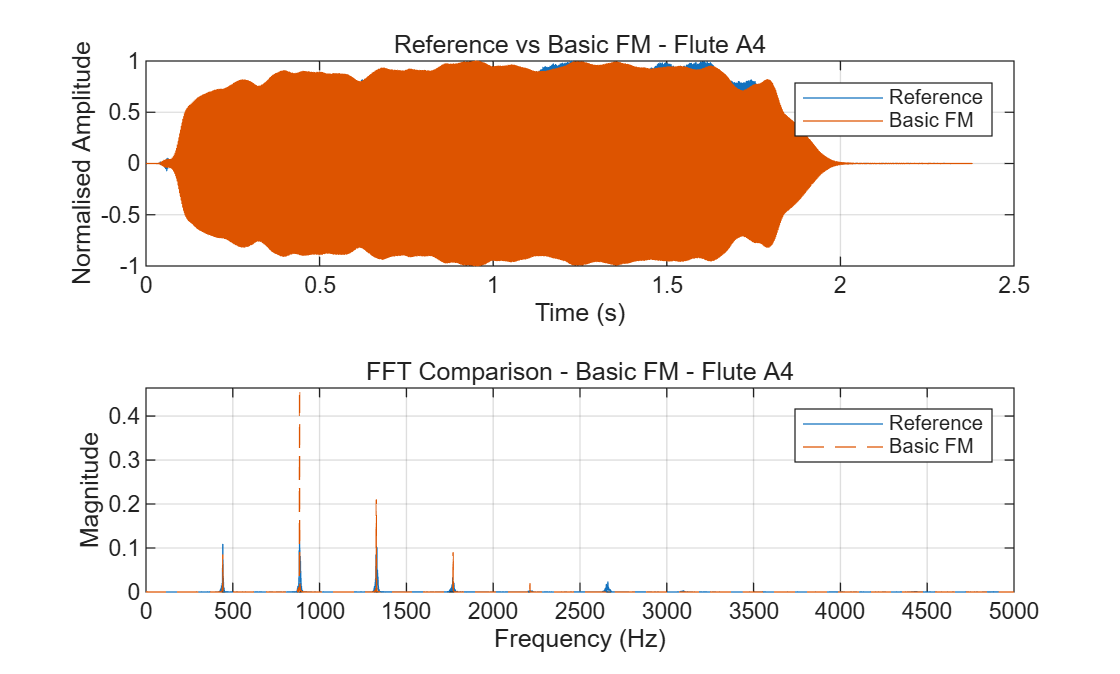


A4 Basic FM Parameters:


Fundamental Frequency = 442.25 Hz


Carrier Frequency = 442.25 Hz


Modulator Frequency = 442.25 Hz


Modulation Index = 2.00


% Fundamental frequencies measured from the reference recordings
f0Values = [260.79, 329.73, 442.25];

% Initial FM parameters
carrierRatio = 1.0;
modulatorRatio = 1.0;
modulationIndex = 2.0;

for i = 1:length(files)

    %% ---------- Read Reference Audio ----------

    [xRef, fs] = audioread(files{i});

    % Convert stereo to mono if necessary
    if size(xRef,2) == 2
        xRef = mean(xRef,2);
    end

    % Normalise reference signal
    xRef = xRef / max(abs(xRef));

    % Time axis
    t = (0:length(xRef)-1)' / fs;

    % Fundamental frequency
    f0 = f0Values(i);


    %% ---------- Extract Reference Amplitude Envelope ----------

    windowSamples = round(0.02 * fs);

    ampEnvelope = sqrt( ...
        movmean(xRef.^2, windowSamples));

    if max(ampEnvelope) > 0
        ampEnvelope = ...
            ampEnvelope / max(ampEnvelope);
    end


    %% ---------- FM Parameters ----------

    carrierFrequency = carrierRatio * f0;

    modulatorFrequency = ...
        modulatorRatio * f0;


    %% ---------- Two-Operator FM Synthesis ----------

    modulator = ...
        modulationIndex * ...
        sin(2*pi*modulatorFrequency*t);

    xFM = sin( ...
        2*pi*carrierFrequency*t + modulator);


    %% ---------- Apply Amplitude Envelope ----------

    xFM = xFM .* ampEnvelope;

    % Normalise synthesized signal
    if max(abs(xFM)) > 0
        xFM = xFM / max(abs(xFM));
    end


    %% ---------- FFT Analysis ----------

    N = length(xRef);

    Xref = fft(xRef);
    Xfm = fft(xFM);

    Pref = abs(Xref / N);
    Pfm = abs(Xfm / N);

    Pref = Pref(1:floor(N/2)+1);
    Pfm = Pfm(1:floor(N/2)+1);

    if length(Pref) > 2

        Pref(2:end-1) = ...
            2 * Pref(2:end-1);

        Pfm(2:end-1) = ...
            2 * Pfm(2:end-1);

    end

    f = fs * ...
        (0:floor(N/2)) / N;


    %% ---------- Display Results ----------

    figure;

    tiledlayout(2,1);


    % ----- Waveform comparison -----

    nexttile;

    plot(t, xRef);
    hold on;

    plot(t, xFM);

    hold off;

    xlabel('Time (s)');
    ylabel('Normalised Amplitude');

    title(['Reference vs Basic FM - Flute ', ...
        notes{i}]);

    legend('Reference', 'Basic FM');

    grid on;


    % ----- FFT comparison -----

    nexttile;

    plot(f, Pref);
    hold on;

    plot(f, Pfm, '--');

    hold off;

    xlim([0 5000]);

    xlabel('Frequency (Hz)');
    ylabel('Magnitude');

    title(['FFT Comparison - Basic FM - Flute ', ...
        notes{i}]);

    legend('Reference', 'Basic FM');

    grid on;


    % Force Live Script to display current figure
    drawnow;


    %% ---------- Save Synthesized Audio ----------

    outputFile = fullfile( ...
        projectRoot, ...
        'audio_output', ...
        ['Flute_', notes{i}, ...
        '_Basic_FM.wav']);

    audiowrite(outputFile, xFM, fs);


    %% ---------- Print FM Parameters ----------

    fprintf('\n%s Basic FM Parameters:\n', notes{i});

    fprintf('Fundamental Frequency = %.2f Hz\n', f0);

    fprintf('Carrier Frequency = %.2f Hz\n', ...
        carrierFrequency);

    fprintf('Modulator Frequency = %.2f Hz\n', ...
        modulatorFrequency);

    fprintf('Modulation Index = %.2f\n', ...
        modulationIndex);

end

## **Automatic FM Parameter Fitting**

 
 Iteration   Func-count         f(x)         Procedure
     0            1          2394.21         
     1            4          1719.78         initial simplex
     2            5          1719.78         reflect
     3            6          1719.78         reflect
     4            8          1719.78         contract inside
     5           13          1719.78         shrink
     6           15          1558.94         expand
     7           16          1558.94         reflect
     8           18          1486.29         expand
     9           20          1388.98         reflect
    10           21          1388.98         reflect
    11           22          1388.98         reflect
    12           24          1388.98         contract outside
    13           25          1388.98         reflect
    14           30          1388.98         shrink
    15           32          1388.98         contract outside
    16           33          1388.98         reflect
    17           38

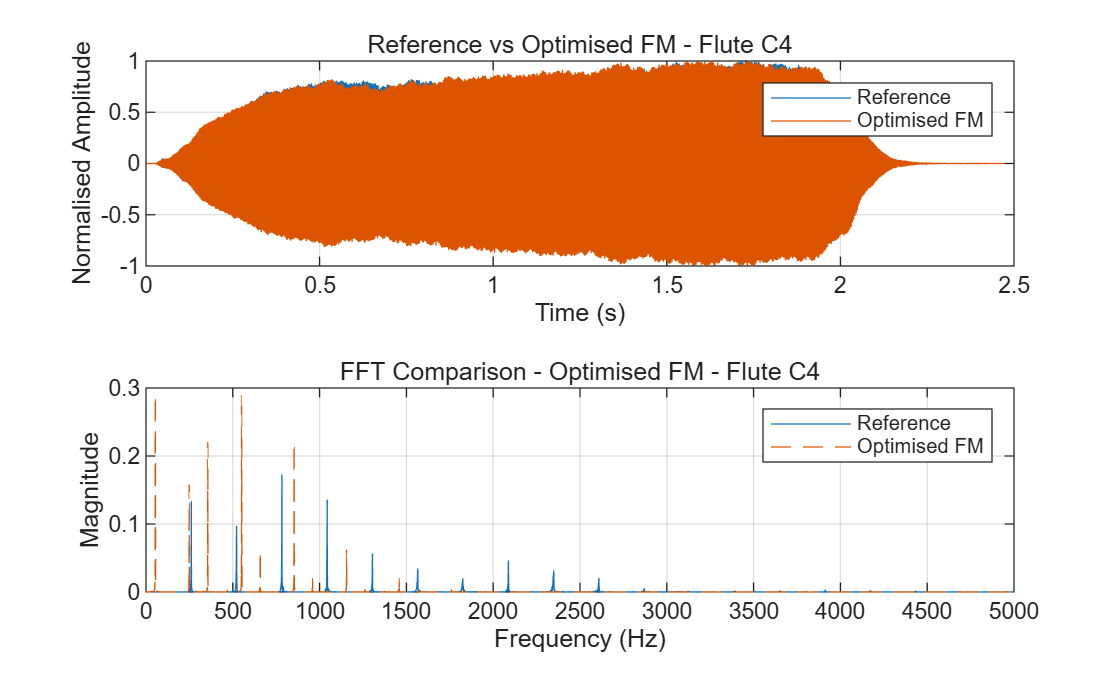


C4 Optimised FM Parameters:


Carrier Ratio = 0.9535


Modulator Ratio = 1.1589


Modulation Index = 1.9614


Carrier Frequency = 248.66 Hz


Modulator Frequency = 302.23 Hz


Final Spectral Cost = 1347.658287


 
 Iteration   Func-count         f(x)         Procedure
     0            1           2322.5         
     1            4          1708.71         initial simplex
     2            5          1708.71         reflect
     3            7          1708.71         contract outside
     4           12          1708.71         shrink
     5           14          1559.98         expand
     6           15          1559.98         reflect
     7           17          1490.15         reflect
     8           19           1426.6         reflect
     9           20           1426.6         reflect
    10           21           1426.6         reflect
    11           23           1426.6         contract inside
    12           28          1400.26         shrink
    13           29          1400.26         reflect
    14           31          1392.31         reflect
    15           32          1392.31         reflect
    16           34          1388.62         contract inside
    17           39

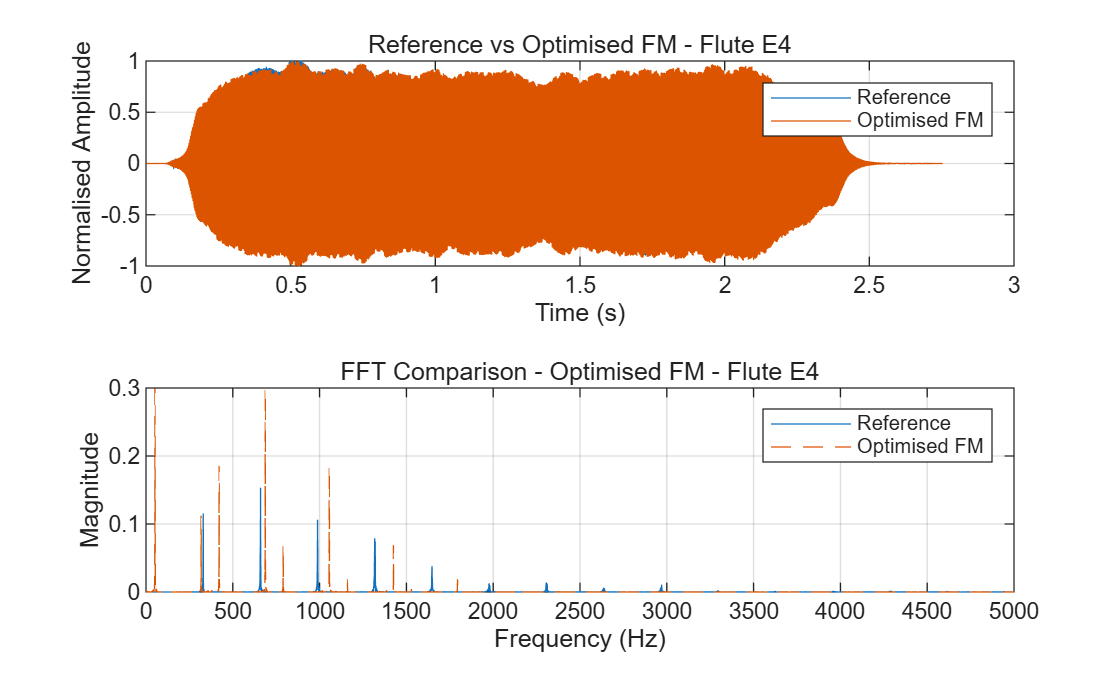


E4 Optimised FM Parameters:


Carrier Ratio = 0.9631


Modulator Ratio = 1.1200


Modulation Index = 2.0153


Carrier Frequency = 317.56 Hz


Modulator Frequency = 369.31 Hz


Final Spectral Cost = 1287.271854


 
 Iteration   Func-count         f(x)         Procedure
     0            1          2355.62         
     1            4          1643.42         initial simplex
     2            5          1643.42         reflect
     3            6          1643.42         reflect
     4           11          1643.42         shrink
     5           13          1304.16         expand
     6           14          1304.16         reflect
     7           16           1214.8         expand
     8           18          1157.85         reflect
     9           19          1157.85         reflect
    10           21          1157.85         contract outside
    11           26          1157.85         shrink
    12           27          1157.85         reflect
    13           28          1157.85         reflect
    14           29          1157.85         reflect
    15           31          1142.69         expand
    16           33          1142.69         contract inside
    17           35          

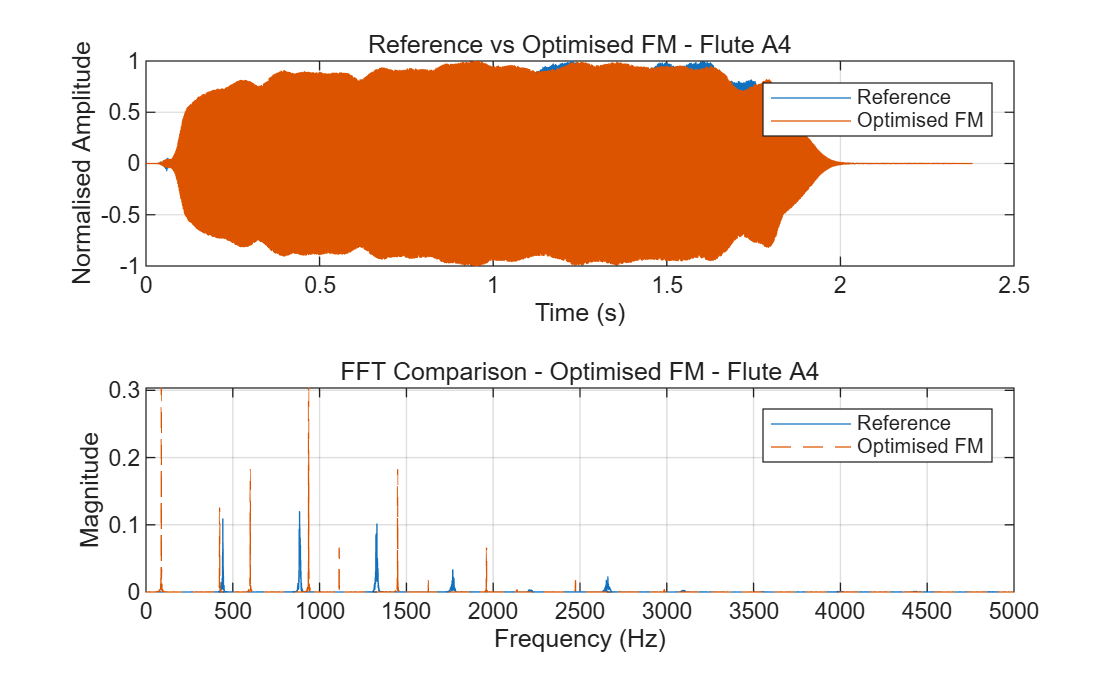


A4 Optimised FM Parameters:


Carrier Ratio = 0.9596


Modulator Ratio = 1.1586


Modulation Index = 1.9748


Carrier Frequency = 424.40 Hz


Modulator Frequency = 512.39 Hz


Final Spectral Cost = 1095.240490



% Fundamental frequencies measured from reference recordings
f0Values = [260.79, 329.73, 442.25];

% Initial parameter guess:
% [carrierRatio, modulatorRatio, modulationIndex]
initialParams = [1.0, 1.0, 2.0];

for i = 1:length(files)

    %% ---------- Read Reference Audio ----------

    [xRef, fs] = audioread(files{i});

    if size(xRef,2) == 2
        xRef = mean(xRef,2);
    end

    xRef = xRef / max(abs(xRef));

    t = (0:length(xRef)-1)' / fs;

    f0 = f0Values(i);


    %% ---------- Extract Reference Amplitude Envelope ----------

    windowSamples = round(0.02 * fs);

    ampEnvelope = sqrt( ...
        movmean(xRef.^2, windowSamples));

    if max(ampEnvelope) > 0
        ampEnvelope = ...
            ampEnvelope / max(ampEnvelope);
    end


    %% ---------- Prepare Reference Spectrum ----------

    N = length(xRef);

    Xref = fft(xRef);

    Pref = abs(Xref / N);

    Pref = Pref(1:floor(N/2)+1);

    if length(Pref) > 2
        Pref(2:end-1) = ...
            2 * Pref(2:end-1);
    end

    f = fs * ...
        (0:floor(N/2)) / N;

    % Only optimise using frequencies below 5 kHz
    freqMask = f <= 5000;

    referenceSpectrum = Pref(freqMask);

    % Normalise reference spectrum
    referenceSpectrum = ...
        referenceSpectrum / ...
        max(referenceSpectrum);


    %% ---------- Define FM Cost Function ----------

    costFunction = @(params) ...
        fmSpectralCost( ...
        params, ...
        f0, ...
        t, ...
        ampEnvelope, ...
        referenceSpectrum, ...
        freqMask, ...
        N);


    %% ---------- Run Optimisation ----------

    options = optimset( ...
        'Display', 'iter', ...
        'MaxIter', 150, ...
        'MaxFunEvals', 500);

    bestParams = fminsearch( ...
        costFunction, ...
        initialParams, ...
        options);


    %% ---------- Extract Optimised Parameters ----------

    carrierRatio = abs(bestParams(1));

    modulatorRatio = abs(bestParams(2));

    modulationIndex = abs(bestParams(3));

    carrierFrequency = ...
        carrierRatio * f0;

    modulatorFrequency = ...
        modulatorRatio * f0;


    %% ---------- Generate Optimised FM Signal ----------

    modulator = ...
        modulationIndex * ...
        sin(2*pi*modulatorFrequency*t);

    xFMfit = sin( ...
        2*pi*carrierFrequency*t + modulator);

    % Apply reference amplitude envelope
    xFMfit = ...
        xFMfit .* ampEnvelope;

    % Normalise
    if max(abs(xFMfit)) > 0
        xFMfit = ...
            xFMfit / max(abs(xFMfit));
    end


    %% ---------- FFT of Optimised FM ----------

    Xfm = fft(xFMfit);

    Pfm = abs(Xfm / N);

    Pfm = Pfm(1:floor(N/2)+1);

    if length(Pfm) > 2
        Pfm(2:end-1) = ...
            2 * Pfm(2:end-1);
    end


    %% ---------- Display Results ----------

    figure;

    tiledlayout(2,1);


    % ----- Waveform comparison -----

    nexttile;

    plot(t, xRef);

    hold on;

    plot(t, xFMfit);

    hold off;

    xlabel('Time (s)');
    ylabel('Normalised Amplitude');

    title(['Reference vs Optimised FM - Flute ', ...
        notes{i}]);

    legend('Reference', 'Optimised FM');

    grid on;


    % ----- FFT comparison -----

    nexttile;

    plot(f, Pref);

    hold on;

    plot(f, Pfm, '--');

    hold off;

    xlim([0 5000]);

    xlabel('Frequency (Hz)');
    ylabel('Magnitude');

    title(['FFT Comparison - Optimised FM - Flute ', ...
        notes{i}]);

    legend('Reference', 'Optimised FM');

    grid on;

    drawnow;


    %% ---------- Print Optimised Parameters ----------

    finalCost = costFunction(bestParams);

    fprintf('\n%s Optimised FM Parameters:\n', ...
        notes{i});

    fprintf('Carrier Ratio = %.4f\n', ...
        carrierRatio);

    fprintf('Modulator Ratio = %.4f\n', ...
        modulatorRatio);

    fprintf('Modulation Index = %.4f\n', ...
        modulationIndex);

    fprintf('Carrier Frequency = %.2f Hz\n', ...
        carrierFrequency);

    fprintf('Modulator Frequency = %.2f Hz\n', ...
        modulatorFrequency);

    fprintf('Final Spectral Cost = %.6f\n', ...
        finalCost);


    %% ---------- Save Optimised FM Audio ----------

    outputFile = fullfile( ...
        projectRoot, ...
        'audio_output', ...
        ['Flute_', notes{i}, ...
        '_Optimised_FM.wav']);

    audiowrite(outputFile, xFMfit, fs);

end



%% Local Function: FM Spectral Cost

function cost = fmSpectralCost( ...
    params, ...
    f0, ...
    t, ...
    ampEnvelope, ...
    referenceSpectrum, ...
    freqMask, ...
    N)

    % Force positive parameter values
    carrierRatio = abs(params(1));
    modulatorRatio = abs(params(2));
    modulationIndex = abs(params(3));

    % Avoid unrealistic values
    if carrierRatio > 6 || ...
       modulatorRatio > 6 || ...
       modulationIndex > 12

        cost = 1e6;
        return;

    end

    % FM frequencies
    fc = carrierRatio * f0;
    fm = modulatorRatio * f0;

    % Generate FM signal
    modulator = ...
        modulationIndex * ...
        sin(2*pi*fm*t);

    xFM = sin( ...
        2*pi*fc*t + modulator);

    % Apply amplitude envelope
    xFM = xFM .* ampEnvelope;

    % Normalise
    if max(abs(xFM)) > 0
        xFM = ...
            xFM / max(abs(xFM));
    end

    % FFT
    X = fft(xFM);

    P = abs(X / N);

    P = P(1:floor(N/2)+1);

    if length(P) > 2
        P(2:end-1) = ...
            2 * P(2:end-1);
    end

    P = P(freqMask);

    % Normalise
    if max(P) > 0
        P = P / max(P);
    end

    % Log spectral comparison
    epsilon = 1e-8;

    refLog = ...
        20 * log10(referenceSpectrum + epsilon);

    synthLog = ...
        20 * log10(P + epsilon);

    % Mean squared log-spectral error
    cost = mean( ...
        (refLog - synthLog).^2);

end